# `Performance Testing / Characterization Script`

Read in JSON File for simulation configuration

clear;

david_file_path = "/home/david/Documents/BlackBoxRadarAttacks/MATLAB/config_files/";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
kristen_file_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
json_text = fileread(david_file_path + "test_config.json");
sim_config = jsondecode(json_text);
json_text_plot = fileread(david_file_path + "plot_config.json");
plot_config = jsondecode(json_text_plot);

Setup parameters from JSON file 

NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = sim_config.TestSettings.Configurations.max_bin;
BIN_WIDTH = sim_config.TestSettings.Configurations.bin_width;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Progress bar initialization

status = sprintf("Current run: %d of %d",1, NUM_RUNS);
progress_bar = waitbar(0,status,"Name","Running Simulation");

Declare the simulation

sim = Simulation_reconfigurable();
values = zeros(0,0);
raw_data = zeros(0,0);

Run simulation for NUM_RUNS, each time with different configuration

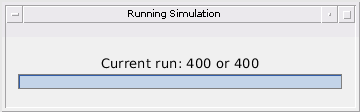

target_velocity = 26

estimated_ranges =    51.1708       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   51.8429       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.7214       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  177.5637   53.4739       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =    51.0000   51.8000   52.6001   53.4001   54.2001   55.0001   55.8002   56.6002   57.4002   58.2002


estimated_velocities =   -23.9162       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.9404       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.9412       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -40.6798  -23.8045       NaN       NaN       NaN       NaN       NaN    

actual_velocities =    -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     1
     2
     1
     3
     3
     2
     2
     2


false_positives =      0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges =     0.1708
    0.0429
    0.1214
    0.0738
    0.0951
    0.1819
    0.0577
    0.1330
    0.0889
    0.0757


percent_error_velocities =     0.0838
    0.0596
    0.0588
    0.1955
    0.0580
    0.0547
    0.0817
    0.0479
    0.1367
    0.0451


target_velocity = -9

estimated_ranges =    63.9563       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   72.5931   63.5176       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  165.8443   63.2317       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   62.7661       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =    64.0000   63.6333   63.2666   62.9000   62.5333   62.1666   61.7999   61.4333   61.0666   60.6999


estimated_velocities =    10.9698       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.7146   10.8784       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.4160   10.9650       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9617       NaN       NaN       NaN       NaN       NaN       NaN    

actual_velocities =     11    11    11    11    11    11    11    11    11    11


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     2
     2
     1
     2
     1
     1
     1
     2
     1


false_positives =      0
     1
     1
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges =     0.0437
    0.1157
    0.0349
    0.1339
    0.0055
    0.0881
    0.0435
    0.0505
    0.0772
    0.0426


percent_error_velocities =     0.0302
    0.1216
    0.0350
    0.0383
    0.0402
    0.0392
    0.0486
    0.0335
    0.1276
    0.0353


target_velocity = -18

estimated_ranges =    11.9941       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.2529       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.4971       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.0146       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =    12.0000   11.3333   10.6666    9.9999    9.3332    8.6666    7.9999    7.3332    6.6665    5.9998


estimated_velocities =    19.9467       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9831       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9590       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9709       NaN       NaN       NaN       NaN       NaN       NaN    

actual_velocities =     20    20    20    20    20    20    20    20    20    20


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =     0.0059
    0.0804
    0.1695
    0.0146
    0.0921
    0.1527
    0.0123
    0.0736
    0.1783
    0.0045


percent_error_velocities =     0.0533
    0.0169
    0.0410
    0.0291
    0.0173
    0.0694
    0.1063
    0.0158
    0.0190
    0.0626


target_velocity = -6

estimated_ranges =    97.6403  132.8415       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.5762       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.5468       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.2502       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =   133.0000  132.7333  132.4666  132.2000  131.9333  131.6666  131.3999  131.1333  130.8666  130.5999


estimated_velocities =   -31.6248    8.0021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.9551       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0175       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0146       NaN       NaN       NaN       NaN       NaN       NaN    

actual_velocities =      8     8     8     8     8     8     8     8     8     8


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      2
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives =      1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges =     0.1585
    0.1571
    0.0801
    0.0502
    0.0077
    0.0294
    0.0900
    0.1122
    0.1673
    0.0219


percent_error_velocities =     0.0021
    0.0449
    0.0175
    0.0146
    0.0079
    0.0164
    0.0157
    0.0023
    0.0019
    0.0993


target_velocity = 22

estimated_ranges =    98.1357       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   85.0178   98.7486       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.8913   99.3881       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.1654       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =    98.0000   98.6667   99.3334  100.0001  100.6668  101.3334  102.0001  102.6668  103.3335  104.0002


estimated_velocities =   -19.9568       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9022  -19.8287       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.6355  -19.9829       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9878       NaN       NaN       NaN       NaN       NaN       NaN    

actual_velocities =    -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     2
     2
     1
     2
     2
     3
     2
     2
     2


false_positives =      0
     1
     1
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges =     0.1357
    0.0819
    0.0547
    0.1654
    0.0202
    0.0535
    0.1469
    0.0815
    0.0615
    0.1382


percent_error_velocities =     0.0432
    0.1713
    0.0171
    0.0122
    0.0995
    0.0274
    0.0318
    0.2405
    0.0142
    0.0333


target_velocity = 6

estimated_ranges =    29.9733       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  104.2666   30.1328       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  178.7843   30.2599       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.4155       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =    30.0000   30.1333   30.2667   30.4000   30.5334   30.6667   30.8000   30.9334   31.0667   31.2000


estimated_velocities =    -3.9749       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.8530   -3.9747       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.3670   -3.9794       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.9789       NaN       NaN       NaN       NaN       NaN       NaN    

actual_velocities =     -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected =      1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     2
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0267
    0.0006
    0.0067
    0.0155
    0.0441
    0.0431
    0.0579
    0.0900
    0.1047
    0.0807


percent_error_velocities = 10×1
    0.0251
    0.0253
    0.0206
    0.0211
    0.0215
    0.0273
    0.0262
    0.0257
    0.0250
    0.0451


target_velocity = 25

estimated_ranges = 10×30
   11.0958       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.8981       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.6046       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.4509       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   11.0000   11.7667   12.5334   13.3001   14.0668   14.8335   15.6001   16.3668   17.1335   17.9002


estimated_velocities = 10×30
  -22.8153       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9538       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9150       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.8856       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     0


percent_error_ranges = 10×1
    0.0958
    0.1314
    0.0712
    0.1509
    0.0974
    0.0443
    0.1569
    0.0947
    0.0631
    0.1229


percent_error_velocities = 10×1
    0.1847
    0.0462
    0.0850
    0.1144
    0.0545
    0.0636
    0.0578
    0.0576
    0.1295
    0.0763


target_velocity = -28

estimated_ranges = 10×30
   13.8504       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.8524       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.8398       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.8425       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   14.0000   13.0000   11.9999   10.9999    9.9999    8.9998    7.9998    6.9998    5.9997    4.9997


estimated_velocities = 10×30
   29.7977       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.8107       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.8462       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.7961       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1496
    0.1476
    0.1601
    0.1574
    0.1519
    0.1656
    0.1646
    0.1556
    0.1700
    0.1722


percent_error_velocities = 10×1
    0.2023
    0.1893
    0.1538
    0.2039
    0.1847
    0.1484
    0.2037
    0.1800
    0.1431
    0.2020


target_velocity = -2

estimated_ranges = 10×30
  134.8753       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  134.7927       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  134.8517       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   91.1641  134.6712       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  135.0000  134.8667  134.7333  134.6000  134.4666  134.3333  134.2000  134.0666  133.9333  133.8000


estimated_velocities = 10×30
    3.9171       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.9740       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.9868       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.5576    3.9511       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1247
    0.0739
    0.1184
    0.0713
    0.0602
    0.0598
    0.0351
    0.0044
    0.0169
    0.0102


percent_error_velocities = 10×1
    0.0829
    0.0260
    0.0132
    0.0489
    0.0572
    0.0193
    0.0230
    0.0121
    0.0251
    0.0139


target_velocity = 33

estimated_ranges = 10×30
   67.1794       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   83.4345   68.1362       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   69.1423       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   70.2896       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   67.0000   68.0334   69.0667   70.1001   71.1335   72.1668   73.2002   74.2336   75.2669   76.3003


estimated_velocities = 10×30
  -30.9522       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -42.3103  -30.9482       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.8888       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.7873       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1794
    0.1029
    0.0755
    0.1895
    0.1793
    0.1378
    0.0657
    0.1856
    0.1850
    0.1372


percent_error_velocities = 10×1
    0.0478
    0.0518
    0.1112
    0.2127
    0.0633
    0.0576
    0.0659
    0.1305
    0.0956
    0.0478


target_velocity = 12

estimated_ranges = 10×30
  192.4957   53.9771       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   56.7361   54.4242       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  102.5414   54.6879       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   54.9853       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   54.0000   54.3333   54.6667   55.0000   55.3334   55.6667   56.0001   56.3334   56.6668   57.0001


estimated_velocities = 10×30
   22.3849   -9.9338       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.4605   -9.9499       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.0938   -9.9798       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.9006       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     2
     1
     1
     2
     2
     3
     2
     2


false_positives = 10×1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0229
    0.0908
    0.0213
    0.0148
    0.1082
    0.0229
    0.0453
    0.1130
    0.0380
    0.0208


percent_error_velocities = 10×1
    0.0662
    0.0501
    0.0202
    0.0994
    0.0344
    0.0214
    0.0465
    0.0291
    0.0298
    0.0675


target_velocity = 18

estimated_ranges = 10×30
   38.0320       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.5613       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.1584       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.7386       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   38.0000   38.5334   39.0667   39.6001   40.1334   40.6668   41.2001   41.7335   42.2668   42.8002


estimated_velocities = 10×30
  -15.8294       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.9618       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.9718       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.9551       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0320
    0.0280
    0.0917
    0.1386
    0.0026
    0.0389
    0.1017
    0.1386
    0.0000
    0.0492


percent_error_velocities = 10×1
    0.1706
    0.0382
    0.0282
    0.0449
    0.0586
    0.0312
    0.0312
    0.0556
    0.0435
    0.0267


target_velocity = -34

estimated_ranges = 10×30
   35.8108       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.6476       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.4729       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.1971       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   36.0000   34.8000   33.5999   32.3999   31.1998   29.9998   28.7998   27.5997   26.3997   25.1997


estimated_velocities = 10×30
   35.8306       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9123       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.7976       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9181       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     0
     0


percent_error_ranges = 10×1
    0.1892
    0.1523
    0.1270
    0.2027
    0.1353
    0.1945
    0.1485
    0.1328
    0.1986
    0.1322


percent_error_velocities = 10×1
    0.1694
    0.0877
    0.2024
    0.0819
    0.1084
    0.1618
    0.0874
    0.2091
    0.0808
    0.1126


target_velocity = -1

estimated_ranges = 10×30
  125.8718       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.9525       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.7696       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.6048       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  126.0000  125.9000  125.8000  125.7000  125.6000  125.5000  125.4000  125.3000  125.2000  125.1000


estimated_velocities = 10×30
    2.9737       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.0198       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.0104       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.9725       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1282
    0.0525
    0.0304
    0.0952
    0.1022
    0.0011
    0.0886
    0.1272
    0.0432
    0.0441


percent_error_velocities = 10×1
    0.0263
    0.0198
    0.0104
    0.0275
    0.0185
    0.0031
    0.0005
    0.0526
    0.0041
    0.0004


target_velocity = 29

estimated_ranges = 10×30
  167.2612   91.1645       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  101.9094   91.9662       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   92.9060       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   93.8710       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   91.0000   91.9000   92.8001   93.7001   94.6001   95.5001   96.4002   97.3002   98.2002   99.1003


estimated_velocities = 10×30
    1.0101  -26.9712       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.2042  -26.9750       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -26.7473       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -26.9031       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     1
     1
     1
     2
     2
     2
     2
     3


false_positives = 10×1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1645
    0.0662
    0.1060
    0.1709
    0.0843
    0.0106
    0.1542
    0.1165
    0.0390
    0.1239


percent_error_velocities = 10×1
    0.0288
    0.0250
    0.2527
    0.0969
    0.0154
    0.0813
    0.1100
    0.0202
    0.1030
    0.2573


target_velocity = -1

estimated_ranges = 10×30
    7.9829       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.8286       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.8675       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   53.0385    7.7168       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    8.0000    7.9000    7.8000    7.7000    7.6000    7.5000    7.4000    7.3000    7.2000    7.1000


estimated_velocities = 10×30
    2.9999       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.9841       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.9873       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.2042    2.9994       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     2
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     1
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0171
    0.0714
    0.0676
    0.0168
    0.0672
    0.0554
    0.0565
    0.0281
    0.1073
    0.0550


percent_error_velocities = 10×1
    0.0001
    0.0159
    0.0127
    0.0006
    0.0007
    0.0451
    0.0006
    0.0007
    0.0079
    0.0229


target_velocity = 11

estimated_ranges = 10×30
   60.9196   93.0570       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   93.3837       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.3520   93.7281       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   93.9952       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   93.0000   93.3000   93.6000   93.9000   94.2000   94.5000   94.8001   95.1001   95.4001   95.7001


estimated_velocities = 10×30
   19.5103   -8.9079       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9492       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -29.1950   -8.9899       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9912       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     2
     1
     1
     3
     2
     2
     3
     3


false_positives = 10×1
     1
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0570
    0.0837
    0.1281
    0.0952
    0.0484
    0.0325
    0.0080
    0.0253
    0.0828
    0.0482


percent_error_velocities = 10×1
    0.0921
    0.0508
    0.0101
    0.0088
    0.0074
    0.0113
    0.0125
    0.0115
    0.0104
    0.1102


target_velocity = 1

estimated_ranges = 10×30
   25.9646       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9914       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.0303       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  192.2828   25.7981       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   26.0000   25.9667   25.9333   25.9000   25.8667   25.8333   25.8000   25.7667   25.7333   25.7000


estimated_velocities = 10×30
    1.0115       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.0106       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.0107       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.2570    1.0106       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0354
    0.0247
    0.0969
    0.1019
    0.0305
    0.0280
    0.0828
    0.0596
    0.0523
    0.0005


percent_error_velocities = 10×1
    0.0115
    0.0106
    0.0107
    0.0106
    0.0102
    0.0116
    0.0107
    0.0066
    0.0110
    0.0119


target_velocity = 18

estimated_ranges = 10×30
  127.1223       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.6316       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  128.0711       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  128.6753       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  127.0000  127.5334  128.0667  128.6001  129.1334  129.6668  130.2001  130.7335  131.2668  131.8002


estimated_velocities = 10×30
  -15.9747       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.8090       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.9655       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.9752       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     2
     2
     2
     3


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1223
    0.0982
    0.0044
    0.0753
    0.1443
    0.0213
    0.0179
    0.0826
    0.1406
    0.0205


percent_error_velocities = 10×1
    0.0253
    0.1910
    0.0345
    0.0248
    0.0394
    0.0972
    0.0370
    0.0360
    0.0594
    0.0402


target_velocity = 33

estimated_ranges = 10×30
   78.1584       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  152.4357   79.1464       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   80.1198       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   81.3261       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   78.0000   79.0334   80.0667   81.1001   82.1335   83.1668   84.2002   85.2336   86.2669   87.3003


estimated_velocities = 10×30
  -30.9424       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.6292  -30.9295       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9237       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9192       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     2
     2
     3
     2
     3


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1584
    0.1131
    0.0531
    0.2260
    0.1593
    0.1193
    0.0571
    0.1885
    0.1922
    0.1141


percent_error_velocities = 10×1
    0.0576
    0.0705
    0.0763
    0.0808
    0.0711
    0.0515
    0.0449
    0.1501
    0.0475
    0.0548


target_velocity = -8

estimated_ranges = 10×30
  121.8811       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  121.6353       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  121.3909       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.9062       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  122.0000  121.6667  121.3333  121.0000  120.6666  120.3333  119.9999  119.6666  119.3332  118.9999


estimated_velocities = 10×30
    9.9781       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9686       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9529       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9450       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1189
    0.0314
    0.0576
    0.0938
    0.0357
    0.0209
    0.1025
    0.0144
    0.0737
    0.1188


percent_error_velocities = 10×1
    0.0219
    0.0314
    0.0471
    0.0550
    0.0250
    0.0852
    0.0401
    0.0210
    0.0620
    0.0381


target_velocity = -27

estimated_ranges = 10×30
  141.8899       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  140.8808       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  139.8819       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  139.0102       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  142.0000  141.0333  140.0666  139.0999  138.1332  137.1665  136.1998  135.2331  134.2664  133.2997


estimated_velocities = 10×30
   28.9637       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.8865       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.8776       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.8115       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1101
    0.1525
    0.1847
    0.0897
    0.0941
    0.1480
         0
    0.0923
    0.0860
    0.1434


percent_error_velocities = 10×1
    0.0363
    0.1135
    0.1224
    0.1885
    0.0588
    0.0717
         0
    0.2111
    0.0500
    0.0638


target_velocity = 25

estimated_ranges = 10×30
  120.1233       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.8080       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  121.6744       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  122.3910       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  120.0000  120.7667  121.5334  122.3001  123.0668  123.8335  124.6001  125.3668  126.1335  126.9002


estimated_velocities = 10×30
  -22.9751       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9451       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.8678       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9606       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     3
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1233
    0.0413
    0.1411
    0.0910
    0.0443
    0.1478
    0.0623
    0.0032
    0.1427
    0.0544


percent_error_velocities = 10×1
    0.0249
    0.0549
    0.1322
    0.0394
    0.0873
    0.0419
    0.0430
    0.1389
    0.0243
    0.0683


target_velocity = -20

estimated_ranges = 10×30
   36.9546       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.1969       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  167.0143   35.4003       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.6696       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   37.0000   36.2666   35.5333   34.7999   34.0666   33.3332   32.5999   31.8665   31.1331   30.3998


estimated_velocities = 10×30
   21.9559       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.8245       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -39.4277   21.8649       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.8883       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0454
    0.0698
    0.1329
    0.1303
    0.1231
    0.1111
    0.0732
    0.0530
    0.0656
    0.1065


percent_error_velocities = 10×1
    0.0441
    0.1755
    0.1351
    0.1117
    0.0886
    0.0350
    0.0383
    0.0362
    0.1522
    0.1600


target_velocity = -11

estimated_ranges = 10×30
   49.9469       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   49.5212       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   49.0987       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   48.6737       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   50.0000   49.5667   49.1333   48.7000   48.2666   47.8333   47.3999   46.9666   46.5332   46.0999


estimated_velocities = 10×30
   12.9852       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9862       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9822       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9766       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     3
     2
     3


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0531
    0.0454
    0.0346
    0.0262
    0.0170
    0.0054
    0.0037
    0.0149
    0.0270
    0.0378


percent_error_velocities = 10×1
    0.0148
    0.0138
    0.0178
    0.0234
    0.0277
    0.0328
    0.0395
    0.0482
    0.0601
    0.0760


target_velocity = -5

estimated_ranges = 10×30
   45.2460   53.9541       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   53.6166       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   53.5486       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.8768   53.2345       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   54.0000   53.7667   53.5333   53.3000   53.0666   52.8333   52.6000   52.3666   52.1333   51.8999


estimated_velocities = 10×30
    0.3897    7.0007       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9936       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9948       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.8599    6.9926       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     2
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0459
    0.1501
    0.0153
    0.0655
    0.0125
    0.0071
    0.1087
    0.0710
    0.0422
    0.1055


percent_error_velocities = 10×1
    0.0007
    0.0064
    0.0052
    0.0074
    0.0400
    0.0010
    0.0044
    0.0090
    0.0015
    0.0171


target_velocity = -24

estimated_ranges = 10×30
   85.8289   73.9323       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   73.0860       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   72.2463       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   71.2960       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   74.0000   73.1333   72.2666   71.3999   70.5332   69.6665   68.7998   67.9331   67.0664   66.1998


estimated_velocities = 10×30
    7.2906   25.9373       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9146       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.8431       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.7809       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     1
     1
     2
     2


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0677
    0.0473
    0.0203
    0.1039
    0.1079
    0.1148
    0.2263
    0.2073
    0.1822
    0.1579


percent_error_velocities = 10×1
    0.0627
    0.0854
    0.1569
    0.2191
    0.2457
    0.2484
    0.0382
    0.0272
    0.0215
    0.0223


target_velocity = 23

estimated_ranges = 10×30
   96.1550       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.7926   96.8340       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.6363       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   98.2007       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   96.0000   96.7000   97.4000   98.1001   98.8001   99.5001  100.2001  100.9002  101.6002  102.3002


estimated_velocities = 10×30
  -20.9772       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -37.5469  -20.8819       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -20.9582       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -20.7777       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     0
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1550
         0
    0.2362
    0.1007
    0.0474
    0.0133
    0.0268
    0.0614
    0.0996
    0.1129


percent_error_velocities = 10×1
    0.0228
         0
    0.0418
    0.2223
    0.0055
    0.0678
    0.0127
    0.0131
    0.0058
    0.0249


target_velocity = -26

estimated_ranges = 10×30
  110.9015       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.8935       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.0204       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  107.9610       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  111.0000  110.0666  109.1333  108.1999  107.2665  106.3332  105.3998  104.4665  103.5331  102.5997


estimated_velocities = 10×30
   27.9428       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.9053       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.9140       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.9676       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0985
    0.1731
    0.1128
    0.2389
    0.0205
    0.1469
    0.0819
    0.1697
    0.0933
    0.1241


percent_error_velocities = 10×1
    0.0572
    0.0947
    0.0860
    0.0324
    0.0378
    0.0703
    0.1005
    0.0447
    0.2146
    0.0649


target_velocity = -12

estimated_ranges = 10×30
   47.9617       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   47.5539       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   46.9047       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   46.5012       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   48.0000   47.5333   47.0666   46.6000   46.1333   45.6666   45.1999   44.7332   44.2665   43.7999


estimated_velocities = 10×30
   13.9973       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.9600       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.9722       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.9977       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0383
    0.0206
    0.1619
    0.0987
    0.0291
    0.0356
    0.1536
    0.0613
    0.0153
    0.0618


percent_error_velocities = 10×1
    0.0027
    0.0400
    0.0278
    0.0023
    0.0155
    0.1442
    0.0008
    0.0051
    0.0003
    0.1524


target_velocity = -32

estimated_ranges = 10×30
   57.8525       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   56.7367       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   55.6198       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.1746   54.4694       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   58.0000   56.8666   55.7333   54.5999   53.4665   52.3332   51.1998   50.0664   48.9330   47.7997


estimated_velocities = 10×30
   33.7451       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7923       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.8715       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.3665   33.8169       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     2
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1475
    0.1300
    0.1134
    0.1304
    0.1346
    0.1024
    0.1440
    0.1536
    0.1551
    0.1966


percent_error_velocities = 10×1
    0.2549
    0.2077
    0.1285
    0.1831
    0.1160
    0.0651
    0.0936
    0.0656
    0.0749
    0.0537


target_velocity = -6

estimated_ranges = 10×30
   84.9245       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.0213   84.6046       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.7003   84.3565       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   84.3075       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   85.0000   84.7333   84.4666   84.2000   83.9333   83.6666   83.3999   83.1333   82.8666   82.5999


estimated_velocities = 10×30
    7.9981       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.4549    8.0032       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.7278    7.9384       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.9999       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     2
     1
     1
     2
     2
     2
     2
     3


false_positives = 10×1
     0
     1
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0755
    0.1287
    0.1101
    0.1076
    0.0404
    0.0227
    0.0349
    0.0594
    0.0946
    0.1464


percent_error_velocities = 10×1
    0.0019
    0.0032
    0.0616
    0.0001
    0.0201
    0.0060
    0.0077
    0.0046
    0.0116
    0.0009


target_velocity = 14

estimated_ranges = 10×30
   13.9738       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.4233       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.4543   14.8749       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.3331       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   14.0000   14.4000   14.8000   15.2000   15.6001   16.0001   16.4001   16.8001   17.2001   17.6001


estimated_velocities = 10×30
  -11.9722       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9798       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.4928  -11.9674       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9741       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     1
     1
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.0262
    0.0232
    0.0749
    0.1331
    0.0560
    0.0025
    0.0418
    0.0848
    0.1265
    0.0652


percent_error_velocities = 10×1
    0.0278
    0.0202
    0.0326
    0.0259
    0.1070
    0.0522
    0.0277
    0.0221
    0.0345
    0.0882


target_velocity = -28

estimated_ranges = 10×30
    6.8448       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.8304       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.8287       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.8413       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    7.0000    6.0000    4.9999    3.9999    2.9999    1.9998    0.9998    0.0002    1.0003    2.0003


estimated_velocities = 10×30
   29.8195       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.8562       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.7978       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.8247       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     1
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.1552
    0.1696
    0.1712
    0.1586
    0.1738
    0.1803
    0.1644
         0
         0
         0


percent_error_velocities = 10×1
    0.1805
    0.1438
    0.2022
    0.1753
    0.1380
    0.0992
    0.1664
         0
         0
         0


target_velocity = -22

estimated_ranges = 10×30
   49.9380       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   49.0611       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   48.3192       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   47.5179       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   50.0000   49.2000   48.3999   47.5999   46.7999   45.9999   45.1998   44.3998   43.5998   42.7998


estimated_velocities = 10×30
   23.9123       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9522       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.8607       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9531       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0620
    0.1389
    0.0807
    0.0820
    0.1547
    0.0340
    0.1296
    0.1109
    0.0949
    0.1689


percent_error_velocities = 10×1
    0.0877
    0.0478
    0.1393
    0.0469
    0.0977
    0.0509
    0.0431
    0.1861
    0.0546
    0.0679


target_velocity = 27

estimated_ranges = 10×30
   42.4844   33.1810       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.8804       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.7062       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.5724       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   33.0000   33.8334   34.6667   35.5001   36.3334   37.1668   38.0002   38.8335   39.6669   40.5002


estimated_velocities = 10×30
   10.8070  -24.9093       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.8909       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.9466       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.9619       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1810
    0.0470
    0.0395
    0.0724
    0.1088
    0.1446
    0.1735
    0.0389
    0.0292
    0.0752


percent_error_velocities = 10×1
    0.0907
    0.1091
    0.0534
    0.0381
    0.0412
    0.0634
    0.1254
    0.2007
    0.0406
    0.0323


target_velocity = -4

estimated_ranges = 10×30
   26.9775       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.2812   26.8732       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.5339       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.4176       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   27.0000   26.8000   26.6000   26.4000   26.2000   26.0000   25.8000   25.6000   25.3999   25.1999


estimated_velocities = 10×30
    5.9889       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.5692    5.9856       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9846       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9793       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     2
     2
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     0
     1
     1
     0
     0


percent_error_ranges = 10×1
    0.0225
    0.0732
    0.0661
    0.0176
    0.0947
    0.0335
    0.0672
    0.0811
    0.0391
    0.1179


percent_error_velocities = 10×1
    0.0111
    0.0144
    0.0154
    0.0207
    0.0315
    0.0116
    0.0228
    0.0123
    0.0120
    0.0204


target_velocity = 35

estimated_ranges = 10×30
  101.1267       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  102.3319       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  103.3498       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  104.4072       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  101.0000  102.1000  103.2001  104.3001  105.4001  106.5002  107.6002  108.7002  109.8003  110.9003


estimated_velocities = 10×30
  -32.9666       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9412       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.7223       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.8927       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     3
     2
     3


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1267
    0.2318
    0.1497
    0.1071
    0.1809
    0.1452
    0.0754
    0.1371
    0.2520
    0.0256


percent_error_velocities = 10×1
    0.0334
    0.0588
    0.2777
    0.1073
    0.0547
    0.2662
    0.0762
    0.0545
    0.0725
    0.0964


target_velocity = 9

estimated_ranges = 10×30
   65.9448       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.2513       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.5869       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  141.9802   66.6392       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   66.0000   66.2333   66.4667   66.7000   66.9334   67.1667   67.4000   67.6334   67.8667   68.1001


estimated_velocities = 10×30
   -6.9784       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.0001       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9882       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -26.4291   -6.9979       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0552
    0.0180
    0.1202
    0.0609
    0.0581
    0.1047
    0.0089
    0.0656
    0.0550
    0.0014


percent_error_velocities = 10×1
    0.0216
    0.0001
    0.0118
    0.0021
    0.0015
    0.0449
    0.0078
    0.0038
    0.0592
    0.0026


target_velocity = -14

estimated_ranges = 10×30
   82.9201       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.3399       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   81.9424       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   81.3712       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   83.0000   82.4666   81.9333   81.3999   80.8666   80.3332   79.7999   79.2665   78.7332   78.1998


estimated_velocities = 10×30
   15.9617       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.9166       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.9042       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.9565       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0799
    0.1268
    0.0091
    0.0288
    0.0974
    0.1369
    0.0197
    0.0429
    0.1048
    0.1354


percent_error_velocities = 10×1
    0.0383
    0.0834
    0.0958
    0.0435
    0.0213
    0.1140
    0.0571
    0.0260
    0.0266
    0.1500


target_velocity = -35

estimated_ranges = 10×30
  123.9008       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  122.5728       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  121.3776       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.1663       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  124.0000  122.7666  121.5333  120.2999  119.0665  117.8331  116.5998  115.3664  114.1330  112.8996


estimated_velocities = 10×30
   36.9377       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.9168       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.7212       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.9211       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0992
    0.1939
    0.1556
    0.1336
    0.2021
    0.1038
    0.1385
    0.2038
    0.0722
    0.1688


percent_error_velocities = 10×1
    0.0623
    0.0832
    0.2788
    0.0789
    0.0727
    0.1842
    0.0654
    0.1231
    0.0783
    0.0894


target_velocity = 11

estimated_ranges = 10×30
   26.9672       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.2257       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.6275       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.0055       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   27.0000   27.3000   27.6000   27.9000   28.2000   28.5000   28.8001   29.1001   29.4001   29.7001


estimated_velocities = 10×30
   -8.9819       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9819       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.8816       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9546       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     0


percent_error_ranges = 10×1
    0.0328
    0.0743
    0.0275
    0.1054
    0.0904
    0.1060
    0.0793
    0.0376
    0.0050
    0.0013


percent_error_velocities = 10×1
    0.0181
    0.0181
    0.1184
    0.0454
    0.0405
    0.0027
    0.0012
    0.0009
    0.0039
    0.0165


target_velocity = 24

estimated_ranges = 10×30
   28.1102       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.6096   28.8789       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.5833       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.3097       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   28.0000   28.7334   29.4667   30.2001   30.9334   31.6668   32.4001   33.1335   33.8669   34.6002


estimated_velocities = 10×30
  -21.7980       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.8521  -21.9095       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.9274       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.9683       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     2
     2
     2
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     0
     1
     1
     1
     0


percent_error_ranges = 10×1
    0.1102
    0.1455
    0.1166
    0.1096
    0.0908
    0.0549
    0.0515
    0.0901
    0.1441
    0.1223


percent_error_velocities = 10×1
    0.2020
    0.0905
    0.0726
    0.0317
    0.0447
    0.0509
    0.1731
    0.1949
    0.1102
    0.0888


target_velocity = -24

estimated_ranges = 10×30
  133.8690       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.0212       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.1812       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  131.3350       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  134.0000  133.1333  132.2666  131.3999  130.5332  129.6665  128.7998  127.9331  127.0664  126.1998


estimated_velocities = 10×30
   25.9937       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9687       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9606       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9501       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1310
    0.1121
    0.0854
    0.0649
    0.0452
    0.0128
    0.1021
    0.1168
    0.1091
    0.2426


percent_error_velocities = 10×1
    0.0063
    0.0313
    0.0394
    0.0499
    0.0663
    0.1225
    0.2249
    0.2567
    0.3042
    0.0375


target_velocity = -20

estimated_ranges = 10×30
  156.1445  101.9137       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   83.7396  101.2368       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.4790       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   99.7488       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  102.0000  101.2666  100.5333   99.7999   99.0666   98.3332   97.5999   96.8665   96.1331   95.3998


estimated_velocities = 10×30
   24.9916   21.9723       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.5597   21.9844       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.8734       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.8273       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0863
    0.0299
    0.0542
    0.0512
    0.1381
    0.1576
    0.1535
    0.0970
    0.0647
    0.0685


percent_error_velocities = 10×1
    0.0277
    0.0156
    0.1266
    0.1727
    0.1597
    0.0297
    0.0215
    0.0375
    0.0464
    0.1024


target_velocity = -1

estimated_ranges = 10×30
  111.8581       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   72.3982  111.9838       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.7910       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.6013       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  112.0000  111.9000  111.8000  111.7000  111.6000  111.5000  111.4000  111.3000  111.2000  111.1000


estimated_velocities = 10×30
    3.0178       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.6004    2.9948       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.0049       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.0046       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     1
     3


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1419
    0.0838
    0.0090
    0.0987
    0.1194
    0.0291
    0.0625
    0.1336
    0.0600
    0.0188


percent_error_velocities = 10×1
    0.0178
    0.0052
    0.0049
    0.0046
    0.0441
    0.0007
    0.0067
    0.0087
    0.0196
    0.0106


target_velocity = 20

estimated_ranges = 10×30
   35.0352       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  191.7126   35.7485       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.3087       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.8512       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   35.0000   35.6000   36.2000   36.8001   37.4001   38.0001   38.6001   39.2001   39.8002   40.4002


estimated_velocities = 10×30
  -17.8461       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.8118  -17.9459       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9691       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9649       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0352
    0.1485
    0.1087
    0.0511
    0.0269
    0.0568
    0.1465
    0.1057
    0.0485
    0.0252


percent_error_velocities = 10×1
    0.1539
    0.0541
    0.0309
    0.0351
    0.0692
    0.1522
    0.0526
    0.0305
    0.0351
    0.0748


target_velocity = -5

estimated_ranges = 10×30
  158.2935   86.9200       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   86.8633       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  144.2752   86.5187       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   86.1848       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   87.0000   86.7667   86.5333   86.3000   86.0666   85.8333   85.6000   85.3666   85.1333   84.8999


estimated_velocities = 10×30
  -40.4931    7.0025       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.0036       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.1651    7.0046       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.0068       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     2
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     1
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0800
    0.0967
    0.0146
    0.1152
    0.0490
    0.0267
    0.1378
    0.0399
    0.0732
    0.0186


percent_error_velocities = 10×1
    0.0025
    0.0036
    0.0046
    0.0068
    0.0156
    0.0004
    0.0150
    0.0052
    0.0008
    0.0460


target_velocity = 16

estimated_ranges = 10×30
   17.3348  113.1380       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.5261       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.9181       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  114.4564       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  113.0000  113.4667  113.9334  114.4000  114.8667  115.3334  115.8001  116.2668  116.7335  117.2001


estimated_velocities = 10×30
   37.2483  -13.9621       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0006       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0008       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.8853       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1380
    0.0594
    0.0153
    0.0564
    0.1195
    0.0564
    0.0238
    0.2048
    0.1194
    0.0214


percent_error_velocities = 10×1
    0.0379
    0.0006
    0.0008
    0.1147
    0.0218
    0.0067
    0.0395
    0.0441
    0.0088
    0.0102


target_velocity = -1

estimated_ranges = 10×30
  140.8654       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  140.9210       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  210.3124  140.7525       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  140.5563       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  141.0000  140.9000  140.8000  140.7000  140.6000  140.5000  140.4000  140.3000  140.2000  140.1000


estimated_velocities = 10×30
    2.8963       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.0279       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.3477    3.0381       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.9066       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     1     0     1     1


col_detection = 10×1
     1
     1
     2
     1
     2
     3
     2
     0
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1346
    0.0210
    0.0475
    0.1437
    0.0756
    0.0101
    0.1166
         0
    0.0311
    0.0470


percent_error_velocities = 10×1
    0.1037
    0.0279
    0.0381
    0.0934
    0.0531
    0.0121
    0.0012
         0
    0.0267
    0.0351


target_velocity = 21

estimated_ranges = 10×30
   47.1446       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  163.3801   47.7280       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.4432   48.2461       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   49.0224       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   47.0000   47.6334   48.2667   48.9001   49.5334   50.1668   50.8001   51.4335   52.0668   52.7002


estimated_velocities = 10×30
  -18.8604       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -26.5764  -18.9782       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -35.8167  -18.9558       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -18.9742       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     2
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     1
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1446
    0.0946
    0.0206
    0.1224
    0.0033
    0.1507
    0.0347
    0.1650
    0.0726
    0.0354


percent_error_velocities = 10×1
    0.1396
    0.0218
    0.0442
    0.0258
    0.0250
    0.0373
    0.0184
    0.0701
    0.0224
    0.1030


target_velocity = -22

estimated_ranges = 10×30
   46.9223  117.9096       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  117.0040       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.3278  116.3327       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.5937  115.4398       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  118.0000  117.2000  116.3999  115.5999  114.7999  113.9999  113.1998  112.3998  111.5998  110.7998


estimated_velocities = 10×30
    6.4189   23.9645       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9263       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.6809   23.9414       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -41.8106   23.9660       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     2
     2
     2
     2
     2
     1
     1
     1


false_positives = 10×1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0904
    0.1960
    0.0672
    0.1602
    0.0215
    0.0935
    0.1638
    0.0345
    0.1361
    0.0440


percent_error_velocities = 10×1
    0.0355
    0.0737
    0.0586
    0.0340
    0.1011
    0.0441
    0.1133
    0.0423
    0.0870
    0.1725


target_velocity = 11

estimated_ranges = 10×30
   40.9332       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.2977       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.4779   41.6830       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.9941       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   41.0000   41.3000   41.6000   41.9000   42.2000   42.5000   42.8001   43.1001   43.4001   43.7001


estimated_velocities = 10×30
   -8.9889       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.8971       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -40.4193   -8.9321       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9390       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     2
     2
     2
     3
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0668
    0.0023
    0.0830
    0.0940
    0.1254
    0.0909
    0.0485
    0.0199
    0.0121
    0.0280


percent_error_velocities = 10×1
    0.0111
    0.1029
    0.0679
    0.0610
    0.0002
    0.0012
    0.0000
    0.0034
    0.0106
    0.0101


target_velocity = -34

estimated_ranges = 10×30
  115.8732       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  154.5800  114.5889       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.4606       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   91.9682  112.2593       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  116.0000  114.8000  113.5999  112.3999  111.1998  109.9998  108.7998  107.5997  106.3997  105.1997


estimated_velocities = 10×30
   35.8681       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.2284   35.8608       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9089       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.5645   35.7694       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     2
     1
     1
     2
     2
     1
     1


false_positives = 10×1
     0
     1
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1268
    0.2111
    0.1393
    0.1405
    0.1747
    0.1279
    0.2052
    0.1346
    0.1439
    0.1776


percent_error_velocities = 10×1
    0.1319
    0.1392
    0.0911
    0.2306
    0.0480
    0.1464
    0.1164
    0.0789
    0.2358
    0.0809


target_velocity = -22

estimated_ranges = 10×30
   75.9450       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.0426       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.3568       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   73.4811       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   76.0000   75.2000   74.3999   73.5999   72.7999   71.9999   71.1998   70.3998   69.5998   68.7998


estimated_velocities = 10×30
   23.9578       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9552       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.8641       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9518       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0550
    0.1574
    0.0431
    0.1188
    0.1750
    0.0624
    0.1434
    0.0191
    0.1029
    0.1903


percent_error_velocities = 10×1
    0.0422
    0.0448
    0.1359
    0.0482
    0.0928
    0.0547
    0.0678
    0.0687
    0.0492
    0.0678


target_velocity = 3

estimated_ranges = 10×30
  115.1872  114.8526       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  115.1379       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  115.0882       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  115.0485       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  115.0000  115.0333  115.0667  115.1000  115.1333  115.1667  115.2000  115.2333  115.2667  115.3000


estimated_velocities = 10×30
   16.8822   -1.0137       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0119       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0155       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0159       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1474
    0.1045
    0.0216
    0.0515
    0.1178
    0.0894
    0.0326
    0.0283
    0.0696
    0.0960


percent_error_velocities = 10×1
    0.0137
    0.0119
    0.0155
    0.0159
    0.0210
    0.0103
    0.0107
    0.0118
    0.0083
    0.0287


target_velocity = 16

estimated_ranges = 10×30
  113.2556    6.9956       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.6406       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0416       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.4246       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    7.0000    7.4667    7.9334    8.4000    8.8667    9.3334    9.8001   10.2668   10.7335   11.2001


estimated_velocities = 10×30
  -12.1690  -13.9529       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.9763       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0016       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0005       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0044
    0.1739
    0.1082
    0.0246
    0.0442
    0.1346
    0.0764
    0.0135
    0.0063
    0.1392


percent_error_velocities = 10×1
    0.0471
    0.0237
    0.0016
    0.0005
    0.0192
    0.0600
    0.0067
    0.0080
    0.0775
    0.0159


target_velocity = 12

estimated_ranges = 10×30
   92.0914       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   92.4157       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   77.7488   92.6661       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   93.1068       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   92.0000   92.3333   92.6667   93.0000   93.3334   93.6667   94.0001   94.3334   94.6668   95.0001


estimated_velocities = 10×30
   -9.8955       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.9763       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.2179   -9.9675       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.9161       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     2
     3
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0914
    0.0824
    0.0006
    0.1068
    0.0620
    0.0227
    0.1272
    0.0727
    0.0124
    0.0960


percent_error_velocities = 10×1
    0.1045
    0.0237
    0.0325
    0.0839
    0.0319
    0.0250
    0.0524
    0.0317
    0.0281
    0.1048


target_velocity = -5

estimated_ranges = 10×30
  213.8552    7.9837       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.6814       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   70.6343    7.5873       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.2736       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    8.0000    7.7667    7.5333    7.3000    7.0666    6.8333    6.6000    6.3666    6.1333    5.8999


estimated_velocities = 10×30
  -17.1341    6.9964       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9908       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.4614    6.9652       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.0008       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     2
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0163
    0.0853
    0.0540
    0.0264
    0.1258
    0.0316
    0.0441
    0.1048
    0.0255
    0.0864


percent_error_velocities = 10×1
    0.0036
    0.0092
    0.0348
    0.0008
    0.0025
    0.0086
    0.0040
    0.0220
    0.0005
    0.0006


target_velocity = -27

estimated_ranges = 10×30
   16.8763       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.9412       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.9553       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.9385       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   17.0000   16.0333   15.0666   14.0999   13.1332   12.1665   11.1998   10.2331    9.2664    8.2997


estimated_velocities = 10×30
   28.7932       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.8471       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.9343       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.9214       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1237
    0.0922
    0.1113
    0.1614
    0.1547
    0.0941
    0.0988
    0.1498
    0.1722
    0.1110


percent_error_velocities = 10×1
    0.2068
    0.1529
    0.0657
    0.0786
    0.2104
    0.1850
    0.0676
    0.0691
    0.0838
    0.2084


target_velocity = 32

estimated_ranges = 10×30
   20.1693       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  101.2943   21.1831       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.1942       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.1698       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   20.0000   21.0000   22.0001   23.0001   24.0001   25.0002   26.0002   27.0002   28.0003   29.0003


estimated_velocities = 10×30
  -29.8564       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.7153  -29.8917       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -29.9219       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -29.8612       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    0.1693
    0.1831
    0.1941
    0.1697
    0.1829
    0.1944
    0.1699
    0.1830
    0.1939
    0.1690


percent_error_velocities = 10×1
    0.1436
    0.1083
    0.0781
    0.1388
    0.1042
    0.0753
    0.1336
    0.1005
    0.0736
    0.1295


target_velocity = -14

estimated_ranges = 10×30
   56.1357   42.9687       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   42.3804       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.7973       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.3749       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   43.0000   42.4666   41.9333   41.3999   40.8666   40.3332   39.7999   39.2665   38.7332   38.1998


estimated_velocities = 10×30
   12.6097   15.9727       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.9623       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.9230       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.8808       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0313
    0.0862
    0.1360
    0.0250
    0.0450
    0.0965
    0.1222
    0.0297
    0.0555
    0.1063


percent_error_velocities = 10×1
    0.0273
    0.0377
    0.0770
    0.1192
    0.0248
    0.0478
    0.0997
    0.0926
    0.0274
    0.0603


target_velocity = -1

estimated_ranges = 10×30
   98.9084       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.2449   98.9825       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   98.7973       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.7258   98.6320       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   99.0000   98.9000   98.8000   98.7000   98.6000   98.5000   98.4000   98.3000   98.2000   98.1000


estimated_velocities = 10×30
    2.9906       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.5679    2.9554       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.9832       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.4163    3.0042       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     2
     1
     3
     3
     2
     3
     2


false_positives = 10×1
     0
     1
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0916
    0.0825
    0.0027
    0.0680
    0.0419
    0.0313
    0.0597
    0.1497
    0.0756
    0.0169


percent_error_velocities = 10×1
    0.0094
    0.0446
    0.0168
    0.0042
    0.0352
    0.0012
    0.0108
    0.0044
    0.0059
    0.0020


target_velocity = 13

estimated_ranges = 10×30
   90.1105       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.3788       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.8383       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   91.0694       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   90.0000   90.3667   90.7334   91.1000   91.4667   91.8334   92.2001   92.5667   92.9334   93.3001


estimated_velocities = 10×30
  -10.9308       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9672       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9452       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9643       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1105
    0.0121
    0.1049
    0.0306
    0.0920
    0.0206
    0.0651
    0.0981
    0.0182
    0.1108


percent_error_velocities = 10×1
    0.0692
    0.0328
    0.0548
    0.0357
    0.0252
    0.1002
    0.0347
    0.0782
    0.0211
    0.0504


target_velocity = -20

estimated_ranges = 10×30
  128.3521   69.9635       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   69.2002       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  189.9485   68.4705       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.6748       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   70.0000   69.2666   68.5333   67.7999   67.0666   66.3332   65.5999   64.8665   64.1331   63.3998


estimated_velocities = 10×30
   40.4664   21.9800       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.8816       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.6002   21.8614       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.8295       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     2
     1
     1
     1
     2
     2
     1
     2


false_positives = 10×1
     1
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0365
    0.0665
    0.0628
    0.1251
    0.1413
    0.1311
    0.0950
    0.0501
    0.0673
    0.0509


percent_error_velocities = 10×1
    0.0200
    0.1184
    0.1386
    0.1705
    0.1422
    0.0399
    0.0325
    0.0259
    0.0970
    0.1168


target_velocity = -31

estimated_ranges = 10×30
   86.9430       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   85.7648       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   84.5705       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   83.5680       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   87.0000   85.9000   84.7999   83.6999   82.5999   81.4998   80.3998   79.2998   78.1997   77.0997


estimated_velocities = 10×30
   32.9074       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.9539       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.9204       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.7291       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0570
    0.1352
    0.2294
    0.1319
    0.1153
    0.1864
    0.1461
    0.0719
    0.1707
    0.1733


percent_error_velocities = 10×1
    0.0926
    0.0461
    0.0796
    0.2709
    0.0575
    0.0843
    0.2714
    0.0676
    0.0357
    0.1333


target_velocity = 19

estimated_ranges = 10×30
   47.0777       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  114.8232   47.6160       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   48.1760       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   48.6933       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   47.0000   47.5667   48.1334   48.7001   49.2667   49.8334   50.4001   50.9668   51.5335   52.1002


estimated_velocities = 10×30
  -16.8438       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.3260  -16.8763       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.8549       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9330       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     2
     3
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0777
    0.0493
    0.0426
    0.0067
    0.0068
    0.0205
    0.0046
    0.0109
    0.0309
    0.0174


percent_error_velocities = 10×1
    0.1562
    0.1237
    0.1451
    0.0670
    0.0831
    0.1000
    0.0514
    0.0582
    0.0688
    0.0424


target_velocity = -5

estimated_ranges = 10×30
  120.8684       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.8016       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.5011       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.1518       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  121.0000  120.7667  120.5333  120.3000  120.0666  119.8333  119.6000  119.3666  119.1333  118.8999


estimated_velocities = 10×30
    6.9836       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9987       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.0065       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9835       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1316
    0.0349
    0.0322
    0.1481
    0.0389
    0.0837
    0.0550
    0.0006
    0.0979
    0.0964


percent_error_velocities = 10×1
    0.0164
    0.0013
    0.0065
    0.0165
    0.0036
    0.0006
    0.0339
    0.0058
    0.0145
    0.0208


target_velocity = -12

estimated_ranges = 10×30
   79.9190       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.5327       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9529   79.0114       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   78.4737       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   80.0000   79.5333   79.0666   78.6000   78.1333   77.6666   77.1999   76.7332   76.2665   75.7999


estimated_velocities = 10×30
   14.0008       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.9775       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -34.3718   13.8073       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.9998       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     2
     1
     2
     1


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0810
    0.0006
    0.0552
    0.1262
    0.0392
    0.0378
    0.1499
    0.0985
    0.0310
    0.0265


percent_error_velocities = 10×1
    0.0008
    0.0225
    0.1927
    0.0002
    0.0004
    0.0111
    0.0990
    0.0030
    0.0028
    0.0523


target_velocity = 35

estimated_ranges = 10×30
   25.2790   30.2070       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  145.2279   31.2452       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.3073       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.4690       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   30.0000   31.1000   32.2001   33.3001   34.4001   35.5002   36.6002   37.7002   38.8003   39.9003


estimated_velocities = 10×30
   37.9792  -32.9128       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9615  -32.7399       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9269       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9206       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     1
     1
     1
     1
     2
     3
     2
     2


false_positives = 10×1
     1
     1
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.2070
    0.1452
    0.1072
    0.1689
    0.1473
    0.0599
    0.1590
    0.1667
    0.1407
    0.1239


percent_error_velocities = 10×1
    0.0872
    0.2601
    0.0731
    0.0794
    0.2636
    0.0713
    0.0504
    0.1365
    0.2463
    0.0559


target_velocity = 31

estimated_ranges = 10×30
   36.1707       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.0799       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.0288       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.0132       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   36.0000   36.9667   37.9334   38.9001   39.8668   40.8335   41.8002   42.7669   43.7336   44.7003


estimated_velocities = 10×30
  -28.8921       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.8021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.8621       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.9349       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     2
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     0


percent_error_ranges = 10×1
    0.1707
    0.1132
    0.0954
    0.1131
    0.1632
    0.1527
    0.0936
    0.1017
    0.1532
    0.1796


percent_error_velocities = 10×1
    0.1079
    0.1979
    0.1379
    0.0651
    0.0830
    0.2218
    0.1699
    0.0612
    0.0701
    0.0966


target_velocity = 5

estimated_ranges = 10×30
   81.4479   24.9844       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.1442       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.2613       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.2526       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   25.0000   25.1000   25.2000   25.3000   25.4000   25.5000   25.6000   25.7000   25.8000   25.9000


estimated_velocities = 10×30
   41.8799   -2.9957       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9948       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9685       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9949       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     2
     1
     2
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     0


percent_error_ranges = 10×1
    0.0156
    0.0442
    0.0613
    0.0475
    0.0357
    0.1123
    0.0866
    0.0025
    0.0846
    0.0408


percent_error_velocities = 10×1
    0.0043
    0.0052
    0.0315
    0.0051
    0.0030
    0.0007
    0.0058
    0.0017
    0.0022
    0.0454


target_velocity = -14

estimated_ranges = 10×30
   83.4926   14.9775       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  101.9370   14.3844       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.8131       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.3612       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   15.0000   14.4666   13.9333   13.3999   12.8666   12.3332   11.7999   11.2665   10.7332   10.1998


estimated_velocities = 10×30
   28.0982   15.9462       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.2484   15.9698       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.8972       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.8354       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     1
     1
     1
     2
     1
     1
     1
     2


false_positives = 10×1
     1
     1
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0225
    0.0822
    0.1202
    0.0387
    0.0314
    0.0922
    0.1275
    0.0090
    0.0412
    0.1022


percent_error_velocities = 10×1
    0.0538
    0.0302
    0.1028
    0.1646
    0.0430
    0.0290
    0.1267
    0.0662
    0.0356
    0.0312


target_velocity = -16

estimated_ranges = 10×30
  101.9153       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  101.3507       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.8182       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.0411       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  102.0000  101.4000  100.8000  100.1999   99.5999   98.9999   98.3999   97.7999   97.1998   96.5998


estimated_velocities = 10×30
   17.9665       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9544       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9463       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9203       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     2
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0847
    0.0492
    0.0182
    0.1588
    0.1385
    0.0821
    0.0487
    0.0180
    0.1662
    0.1325


percent_error_velocities = 10×1
    0.0335
    0.0456
    0.0537
    0.0797
    0.0196
    0.0314
    0.0428
    0.0529
    0.0705
    0.0614


target_velocity = 15

estimated_ranges = 10×30
   46.9505       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   47.3948       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   47.8580       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  215.4488   48.4119       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   47.0000   47.4333   47.8667   48.3000   48.7334   49.1667   49.6001   50.0334   50.4668   50.9001


estimated_velocities = 10×30
  -12.9688       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9603       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.8802       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -0.6168  -12.8976       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     2
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0495
    0.0386
    0.0087
    0.1118
    0.1288
    0.1326
    0.1297
    0.1254
    0.1161
    0.1093


percent_error_velocities = 10×1
    0.0312
    0.0397
    0.1198
    0.1024
    0.0829
    0.0667
    0.0557
    0.0441
    0.0361
    0.0300


target_velocity = 35

estimated_ranges = 10×30
   20.1523       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.2302       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  172.9861   22.3004       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.5035       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   20.0000   21.1000   22.2001   23.3001   24.4001   25.5002   26.6002   27.7002   28.8003   29.9003


estimated_velocities = 10×30
  -32.8282       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.7793       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.1515  -32.9518       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9560       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     2
     1
     1
     2
     2
     1


false_positives = 10×1
     0
     0
     1
     0
     1
     0
     0
     1
     1
     0


percent_error_ranges = 10×1
    0.1523
    0.1301
    0.1003
    0.2034
    0.1574
    0.1405
    0.1613
    0.1526
    0.1273
    0.1178


percent_error_velocities = 10×1
    0.1718
    0.2207
    0.0482
    0.0440
    0.2250
    0.1695
    0.0497
    0.2109
    0.1831
    0.0474


target_velocity = -9

estimated_ranges = 10×30
  107.9032       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.3687  107.6869       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.6565  107.2169       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  105.7361  106.7643       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  108.0000  107.6333  107.2666  106.9000  106.5333  106.1666  105.7999  105.4333  105.0666  104.6999


estimated_velocities = 10×30
   10.9622       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.5898   10.9493       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.2505   10.9624       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.8643   10.8699       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     2
     2
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     1
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0968
    0.0536
    0.0497
    0.1357
    0.0411
    0.1377
    0.0052
    0.0969
    0.0488
    0.0503


percent_error_velocities = 10×1
    0.0378
    0.0507
    0.0376
    0.1301
    0.0350
    0.0431
    0.0272
    0.0417
    0.0372
    0.0316


target_velocity = 22

estimated_ranges = 10×30
  144.5557  111.1385       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.7526       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.3914       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.1221       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  111.0000  111.6667  112.3334  113.0001  113.6668  114.3334  115.0001  115.6668  116.3335  117.0002


estimated_velocities = 10×30
   38.9371  -19.9760       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.7538       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9891       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9700       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     3
     2
     2
     3
     2


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1385
    0.0859
    0.0580
    0.1220
    0.0849
    0.0400
    0.1488
    0.0715
    0.0322
    0.1315


percent_error_velocities = 10×1
    0.0240
    0.2462
    0.0109
    0.0300
    0.2356
    0.0227
    0.0150
    0.2219
    0.0048
    0.0182


target_velocity = -3

estimated_ranges = 10×30
  109.8744       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.7795       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.6451       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   91.2121  109.5200       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  110.0000  109.8333  109.6667  109.5000  109.3333  109.1666  109.0000  108.8333  108.6666  108.5000


estimated_velocities = 10×30
    4.9815       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.9678       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.9726       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -33.2202    4.9767       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     2
     2
     3
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1256
    0.0538
    0.0215
    0.0200
    0.0832
    0.0963
    0.1015
    0.0614
    0.0281
    0.0402


percent_error_velocities = 10×1
    0.0185
    0.0322
    0.0274
    0.0233
    0.0174
    0.0460
    0.0390
    0.0236
    0.0151
    0.0303


target_velocity = -11

estimated_ranges = 10×30
   23.9829       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  184.1521   23.5573       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.1317       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.7056       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   24.0000   23.5667   23.1333   22.7000   22.2666   21.8333   21.3999   20.9666   20.5332   20.0999


estimated_velocities = 10×30
   12.9848       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -29.0538   12.9826       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9801       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9757       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     2
     1
     3
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.0171
    0.0094
    0.0016
    0.0056
    0.0122
    0.0170
    0.0190
    0.0165
    0.0046
    0.0262


percent_error_velocities = 10×1
    0.0152
    0.0174
    0.0199
    0.0243
    0.0291
    0.0354
    0.0432
    0.0532
    0.0657
    0.0801


target_velocity = 24

estimated_ranges = 10×30
   40.1295       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.8757       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.5765       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  214.1653   42.3029       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   40.0000   40.7334   41.4667   42.2001   42.9334   43.6668   44.4001   45.1335   45.8669   46.6002


estimated_velocities = 10×30
  -21.8001       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.9265       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.9414       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.7338  -21.9663       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1295
    0.1424
    0.1098
    0.1028
    0.0844
    0.0488
    0.0547
    0.1160
    0.1455
    0.1178


percent_error_velocities = 10×1
    0.1999
    0.0735
    0.0586
    0.0337
    0.0487
    0.0603
    0.1928
    0.2096
    0.0896
    0.0686


target_velocity = -35

estimated_ranges = 10×30
   91.8798       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.5998       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   89.3056       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   88.1989       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   92.0000   90.7666   89.5333   88.2999   87.0665   85.8331   84.5998   83.3664   82.1330   80.8996


estimated_velocities = 10×30
   36.8305       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.9223       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.8774       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.9127       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1202
    0.1668
    0.2276
    0.1010
    0.1656
    0.2003
    0.1145
    0.2006
    0.1428
    0.1459


percent_error_velocities = 10×1
    0.1695
    0.0777
    0.1226
    0.0873
    0.0748
    0.2190
    0.0537
    0.0727
    0.2183
    0.0808


target_velocity = 26

estimated_ranges = 10×30
   32.1495       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.8617       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.5185   33.7579       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.4582       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   32.0000   32.8000   33.6001   34.4001   35.2001   36.0001   36.8002   37.6002   38.4002   39.2002


estimated_velocities = 10×30
  -23.8534       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.9563       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.7881  -23.9554       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.8686       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     2
     3
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1495
    0.0617
    0.1579
    0.0581
    0.1115
    0.1660
    0.0543
    0.1324
    0.0340
    0.1064


percent_error_velocities = 10×1
    0.1466
    0.0437
    0.0446
    0.1314
    0.0480
    0.1011
    0.0535
    0.0692
    0.0701
    0.0526


target_velocity = -1

estimated_ranges = 10×30
  129.7456  128.8920       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   98.7135  128.9522       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  128.7593       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  128.6155       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  129.0000  128.9000  128.8000  128.7000  128.6000  128.5000  128.4000  128.3000  128.2000  128.1000


estimated_velocities = 10×30
  -11.5803    2.9843       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.4824    3.0050       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.9979       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.9632       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     1
     1
     1
     2
     2
     3
     2
     2


false_positives = 10×1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1080
    0.0522
    0.0407
    0.0845
    0.0891
    0.0086
    0.0793
    0.1290
    0.0356
    0.0489


percent_error_velocities = 10×1
    0.0157
    0.0050
    0.0021
    0.0368
    0.0093
    0.0010
    0.0065
    0.0268
    0.0047
    0.0082


target_velocity = 33

estimated_ranges = 10×30
   25.0786   87.1532       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  104.7898   88.1324       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   94.4465   89.1225       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.3198       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   87.0000   88.0334   89.0667   90.1001   91.1335   92.1668   93.2002   94.2336   95.2669   96.3003


estimated_velocities = 10×30
  -16.4110  -30.9457       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -5.5451  -30.9107       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.3062  -30.9122       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9205       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     2
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1532
    0.0990
    0.0557
    0.2197
    0.1510
    0.1076
    0.0521
    0.2035
    0.1802
    0.1030


percent_error_velocities = 10×1
    0.0543
    0.0893
    0.0878
    0.0795
    0.0695
    0.0601
    0.0382
    0.1186
    0.0449
    0.0520


target_velocity = 22

estimated_ranges = 10×30
   72.1744       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   72.6466       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   73.4281       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.1808       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   72.0000   72.6667   73.3334   74.0001   74.6668   75.3334   76.0001   76.6668   77.3335   78.0002


estimated_velocities = 10×30
  -19.9493       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9842       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9917       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9130       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     3
     2
     3


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1744
    0.0201
    0.0947
    0.1807
    0.0079
    0.0757
    0.1943
    0.0116
    0.0862
    0.1692


percent_error_velocities = 10×1
    0.0507
    0.0158
    0.0083
    0.0870
    0.0872
    0.0087
    0.0158
    0.0455
    0.0168
    0.0390


target_velocity = -31

estimated_ranges = 10×30
   55.8657       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   54.7987       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   53.5973       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.5423       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   56.0000   54.9000   53.7999   52.6999   51.5999   50.4998   49.3998   48.2998   47.1997   46.0997


estimated_velocities = 10×30
   32.7639       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.9488       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.9620       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.7846       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1343
    0.1013
    0.2026
    0.1576
    0.0615
    0.1637
    0.1567
    0.1299
    0.1184
    0.2253


percent_error_velocities = 10×1
    0.2361
    0.0512
    0.0380
    0.2154
    0.0433
    0.0452
    0.2043
    0.1978
    0.0474
    0.0424


target_velocity = -2

estimated_ranges = 10×30
   41.9650       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  174.7763   41.7998       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.6709       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.5223       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   42.0000   41.8667   41.7333   41.6000   41.4666   41.3333   41.2000   41.0666   40.9333   40.8000


estimated_velocities = 10×30
    3.9768       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   42.8942    3.9807       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.9688       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.9732       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     2
     2
     3
     2
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0350
    0.0669
    0.0624
    0.0777
    0.1089
    0.1177
    0.0236
    0.0305
    0.0808
    0.0676


percent_error_velocities = 10×1
    0.0232
    0.0193
    0.0312
    0.0268
    0.0288
    0.0192
    0.0561
    0.0491
    0.0295
    0.0263


target_velocity = -15

estimated_ranges = 10×30
   84.9412       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.1802   84.3551       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   83.7674       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   83.2128       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   85.0000   84.4333   83.8666   83.2999   82.7333   82.1666   81.5999   81.0332   80.4665   79.8998


estimated_velocities = 10×30
   16.9584       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0092   16.9622       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9633       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9510       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0588
    0.0782
    0.0992
    0.0871
    0.0952
    0.1187
    0.1125
    0.1138
    0.1378
    0.1440


percent_error_velocities = 10×1
    0.0416
    0.0378
    0.0367
    0.0490
    0.0459
    0.0384
    0.0648
    0.0514
    0.0451
    0.0482


target_velocity = 13

estimated_ranges = 10×30
   16.0006       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.4579       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.7193       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.3392   17.1471       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   16.0000   16.3667   16.7334   17.1000   17.4667   17.8334   18.2001   18.5667   18.9334   19.3001


estimated_velocities = 10×30
  -10.9419       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9677       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9303       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.7607  -10.9692       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     1
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0006
    0.0913
    0.0141
    0.0471
    0.0844
    0.0134
    0.1246
    0.0047
    0.0964
    0.0186


percent_error_velocities = 10×1
    0.0581
    0.0323
    0.0697
    0.0308
    0.0956
    0.0282
    0.0347
    0.0541
    0.0335
    0.0636


target_velocity = -18

estimated_ranges = 10×30
   83.9310       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  187.6097   83.1625       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.6688       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   81.9424       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   84.0000   83.3333   82.6666   81.9999   81.3332   80.6666   79.9999   79.3332   78.6665   77.9998


estimated_velocities = 10×30
   19.9856       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.5037   19.9854       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.8979       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9846       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     2
     3
     2
     3
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0690
    0.1708
    0.0022
    0.0576
    0.1681
    0.0366
    0.0779
    0.1485
    0.0666
    0.0662


percent_error_velocities = 10×1
    0.0144
    0.0146
    0.1021
    0.0154
    0.0182
    0.0597
    0.0259
    0.0309
    0.1851
    0.0148


target_velocity = 30

estimated_ranges = 10×30
   21.1582       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.0406       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.0258       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9026       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   21.0000   21.9334   22.8667   23.8001   24.7335   25.6668   26.6002   27.5335   28.4669   29.4003


estimated_velocities = 10×30
  -27.8587       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9221       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9335       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.8556       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1582
    0.1073
    0.1590
    0.1025
    0.1402
    0.0809
    0.1479
    0.0976
    0.1564
    0.1168


percent_error_velocities = 10×1
    0.1413
    0.0779
    0.0665
    0.1444
    0.1147
    0.0951
    0.0609
    0.1739
    0.0421
    0.2279


target_velocity = 1

estimated_ranges = 10×30
  105.8540       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  105.9383       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  105.9575       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.9551  105.9877       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  106.0000  105.9667  105.9333  105.9000  105.8667  105.8333  105.8000  105.7667  105.7333  105.7000


estimated_velocities = 10×30
    0.9903       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.0088       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.9952       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.9213    1.0147       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     2
     3
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1460
    0.0284
    0.0242
    0.0877
    0.0746
    0.0657
    0.0088
    0.0444
    0.0468
    0.1082


percent_error_velocities = 10×1
    0.0097
    0.0088
    0.0048
    0.0147
    0.0014
    0.0249
    0.0174
    0.0045
    0.0231
    0.0026


target_velocity = 19

estimated_ranges = 10×30
   57.1270       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   57.6871       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   58.1855       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   58.7273       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   57.0000   57.5667   58.1334   58.7001   59.2667   59.8334   60.4001   60.9668   61.5335   62.1002


estimated_velocities = 10×30
  -16.8963       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.8326       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.8322       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.8977       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     3
     2
     2
     2
     3


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1270
    0.1205
    0.0521
    0.0272
    0.0272
    0.0131
    0.0040
    0.0184
    0.0011
    0.0136


percent_error_velocities = 10×1
    0.1037
    0.1674
    0.1678
    0.1023
    0.1269
    0.0583
    0.0736
    0.0967
    0.0422
    0.0587


target_velocity = 20

estimated_ranges = 10×30
   63.1511       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   63.7344       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   64.2730       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   64.8435       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   63.0000   63.6000   64.2000   64.8001   65.4001   66.0001   66.6001   67.2001   67.8002   68.4002


estimated_velocities = 10×30
  -17.9197       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9690       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9680       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9508       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     2
     3
     2
     3


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1511
    0.1344
    0.0729
    0.0434
    0.0200
    0.1571
    0.1348
    0.0674
    0.0386
    0.0213


percent_error_velocities = 10×1
    0.0803
    0.0310
    0.0320
    0.0492
    0.0503
    0.0769
    0.0347
    0.0326
    0.0535
    0.0529


target_velocity = 25

estimated_ranges = 10×30
  141.1090       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  141.7840       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  142.6698       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  143.3885       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  141.0000  141.7667  142.5334  143.3001  144.0668  144.8335  145.6001  146.3668  147.1335  147.9002


estimated_velocities = 10×30
  -22.9407       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9359       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.8816       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9559       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     3
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1090
    0.0173
    0.1364
    0.0885
    0.0778
    0.1416
    0.0469
    0.2096
    0.1273
    0.0393


percent_error_velocities = 10×1
    0.0593
    0.0641
    0.1184
    0.0441
    0.1495
    0.0474
    0.0228
    0.0596
    0.0142
    0.0921


target_velocity = -28

estimated_ranges = 10×30
  120.9020       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   59.1059  119.8965       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  139.3998  118.8789       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  190.2802  117.9034       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  121.0000  120.0000  118.9999  117.9999  116.9999  115.9998  114.9998  113.9998  112.9997  111.9997


estimated_velocities = 10×30
   29.9621       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -36.1011   29.9467       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9655   29.9407       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.5120   29.9529       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     2
     2
     1
     1
     1
     1
     2
     2


false_positives = 10×1
     0
     1
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0980
    0.1034
    0.1210
    0.0965
    0.1004
    0.1106
    0.0962
    0.0995
    0.1087
    0.0888


percent_error_velocities = 10×1
    0.0379
    0.0533
    0.0593
    0.0471
    0.0577
    0.0672
    0.0490
    0.0510
    0.0716
    0.0556


target_velocity = -22

estimated_ranges = 10×30
   66.9516       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.0513       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   65.3425       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  184.7573   64.4912       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   67.0000   66.2000   65.3999   64.5999   63.7999   62.9999   62.1998   61.3998   60.5998   59.7998


estimated_velocities = 10×30
   23.9548       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9650       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.8489       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.0444   23.9545       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0484
    0.1487
    0.0575
    0.1087
    0.1776
    0.0552
    0.1342
    0.0338
    0.0904
    0.1893


percent_error_velocities = 10×1
    0.0452
    0.0350
    0.1511
    0.0455
    0.0876
    0.0544
    0.0619
    0.0882
    0.0449
    0.0539


target_velocity = 25

estimated_ranges = 10×30
    9.0843       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  102.7678    9.8839       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.5920       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  172.5813   11.4503       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    9.0000    9.7667   10.5334   11.3001   12.0668   12.8335   13.6001   14.3668   15.1335   15.9002


estimated_velocities = 10×30
  -22.8551       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.2490  -22.9305       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9516       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -34.0500  -22.8187       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     2
     2
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     1
     0
     1
     1
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    0.0843
    0.1172
    0.0586
    0.1502
    0.1151
    0.0448
    0.1370
    0.0887
    0.0745
    0.1403


percent_error_velocities = 10×1
    0.1449
    0.0695
    0.0484
    0.1813
    0.0517
    0.0873
    0.1091
    0.0670
    0.1620
    0.0606


target_velocity = 30

estimated_ranges = 10×30
   77.1366       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   78.0159       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.0146       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.9046       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   77.0000   77.9334   78.8667   79.8001   80.7335   81.6668   82.6002   83.5335   84.4669   85.4003


estimated_velocities = 10×30
  -27.9141       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.8828       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9577       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.7959       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     3
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1366
    0.0825
    0.1479
    0.1045
    0.1363
    0.1260
    0.0942
    0.1621
    0.1026
    0.1658


percent_error_velocities = 10×1
    0.0859
    0.1172
    0.0423
    0.2041
    0.0443
    0.2412
    0.0333
    0.1677
    0.0627
    0.0788


target_velocity = 10

estimated_ranges = 10×30
  107.0702       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  107.1629       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  107.4869       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  107.7838       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  107.0000  107.2667  107.5334  107.8000  108.0667  108.3334  108.6001  108.8667  109.1334  109.4001


estimated_velocities = 10×30
   -7.9080       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0217       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0016       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0088       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0702
    0.1038
    0.0465
    0.0163
    0.0350
    0.0502
    0.1048
    0.1331
    0.0749
    0.0846


percent_error_velocities = 10×1
    0.0920
    0.0217
    0.0016
    0.0088
    0.0075
    0.0058
    0.0041
    0.0029
    0.0471
    0.0476


target_velocity = -17

estimated_ranges = 10×30
  206.0394  128.8924       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  128.3855       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.5902       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.0564       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  129.0000  128.3666  127.7333  127.0999  126.4666  125.8332  125.1999  124.5665  123.9332  123.2998


estimated_velocities = 10×30
    6.6764   18.9921       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.9686       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.9665       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.9735       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1076
    0.0189
    0.1431
    0.0435
    0.1796
    0.0783
    0.0186
    0.1053
    0.0288
    0.1498


percent_error_velocities = 10×1
    0.0079
    0.0314
    0.0335
    0.0265
    0.0581
    0.0070
    0.0656
    0.0075
    0.0291
    0.0219


target_velocity = -19

estimated_ranges = 10×30
   68.9492       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.2294       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.7258   67.4839       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.7743       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   69.0000   68.3000   67.6000   66.8999   66.1999   65.4999   64.7999   64.0998   63.3998   62.6998


estimated_velocities = 10×30
   20.9846       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9844       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.7347   20.9915       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9759       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0508
    0.0705
    0.1161
    0.1256
    0.1759
    0.1988
    0.1172
    0.0761
    0.0469
    0.0013


percent_error_velocities = 10×1
    0.0154
    0.0156
    0.0085
    0.0241
    0.0090
    0.0582
    0.1766
    0.2125
    0.0968
    0.0201


target_velocity = 28

estimated_ranges = 10×30
   75.1678       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.9937   76.0185       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   76.8700       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  186.2435   77.7135       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   75.0000   75.8667   76.7334   77.6001   78.4668   79.3335   80.2002   81.0669   81.9336   82.8002


estimated_velocities = 10×30
  -25.9629       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.1173  -25.9643       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.9730       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.0444  -25.9767       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     2
     1
     2
     2
     2
     3
     2


false_positives = 10×1
     0
     1
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1678
    0.1518
    0.1366
    0.1135
    0.1002
    0.0840
    0.0654
    0.0459
    0.0271
    0.0953


percent_error_velocities = 10×1
    0.0371
    0.0357
    0.0270
    0.0233
    0.0320
    0.0463
    0.0542
    0.0775
    0.1085
    0.1884


target_velocity = -29

estimated_ranges = 10×30
   43.9037       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   42.7777       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.7718       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.8001       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   44.0000   42.9666   41.9333   40.8999   39.8665   38.8332   37.7998   36.7664   35.7331   34.6997


estimated_velocities = 10×30
   30.8244       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.8714       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9439       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9508       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0963
    0.1889
    0.1614
    0.0998
    0.0667
    0.2173
    0.1557
    0.1228
    0.0586
    0.1928


percent_error_velocities = 10×1
    0.1756
    0.1286
    0.0561
    0.0492
    0.1031
    0.0718
    0.0716
    0.0642
    0.0592
    0.1323


target_velocity = 15

estimated_ranges = 10×30
   63.0535       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   63.5556       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   64.0070       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.5636   64.4502       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   63.0000   63.4333   63.8667   64.3000   64.7334   65.1667   65.6001   66.0334   66.4668   66.9001


estimated_velocities = 10×30
  -12.9134       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9343       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9535       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.7965  -12.9564       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     3
     2
     2
     3
     3


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0535
    0.1222
    0.1403
    0.1501
    0.1461
    0.1425
    0.1351
    0.1279
    0.1187
    0.1110


percent_error_velocities = 10×1
    0.0866
    0.0657
    0.0465
    0.0436
    0.0355
    0.0270
    0.0232
    0.0185
    0.0177
    0.0133


target_velocity = 6

estimated_ranges = 10×30
   70.9117       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   71.0830       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   71.2393       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   71.3709       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   71.0000   71.1333   71.2667   71.4000   71.5334   71.6667   71.8000   71.9334   72.0667   72.2000


estimated_velocities = 10×30
   -3.9744       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.9756       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.9691       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.9772       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0883
    0.0504
    0.0274
    0.0291
    0.0053
    0.0285
    0.0236
    0.0391
    0.0716
    0.0871


percent_error_velocities = 10×1
    0.0256
    0.0244
    0.0309
    0.0228
    0.0190
    0.0243
    0.0229
    0.0211
    0.0198
    0.0212


target_velocity = -20

estimated_ranges = 10×30
  119.8982       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  119.2170       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  118.4727       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  117.7599       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  120.0000  119.2666  118.5333  117.7999  117.0666  116.3332  115.5999  114.8665  114.1331  113.3998


estimated_velocities = 10×30
   21.9774       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.9711       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.9081       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.8904       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1018
    0.0496
    0.0606
    0.0400
    0.1008
    0.2423
    0.1476
    0.1014
    0.0651
    0.0783


percent_error_velocities = 10×1
    0.0226
    0.0289
    0.0919
    0.1096
    0.1808
    0.0048
    0.0333
    0.0425
    0.0018
    0.0622


target_velocity = 5

estimated_ranges = 10×30
   26.9733       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.1587       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.3279       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.9816   27.2329       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   27.0000   27.1000   27.2000   27.3000   27.4000   27.5000   27.6000   27.7000   27.8000   27.9000


estimated_velocities = 10×30
   -2.9987       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.0016       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9954       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.6387   -2.9984       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     1
     2
     2
     2
     1


false_positives = 10×1
     0
     0
     0
     1
     0
     0
     1
     1
     1
     0


percent_error_ranges = 10×1
    0.0267
    0.0587
    0.1279
    0.0671
    0.0190
    0.1045
    0.0615
    0.0147
    0.0650
    0.0257


percent_error_velocities = 10×1
    0.0013
    0.0016
    0.0046
    0.0016
    0.0012
    0.0062
    0.0274
    0.0031
    0.0056
    0.0325


target_velocity = -5

estimated_ranges = 10×30
   50.9567       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   50.6172       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.0861   50.5520       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   50.2376       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   51.0000   50.7667   50.5333   50.3000   50.0666   49.8333   49.6000   49.3666   49.1333   48.8999


estimated_velocities = 10×30
    7.0012       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9979       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -20.3441    6.9983       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9980       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0433
    0.1494
    0.0186
    0.0624
    0.0107
    0.0090
    0.1074
    0.0712
    0.0375
    0.1053


percent_error_velocities = 10×1
    0.0012
    0.0021
    0.0017
    0.0020
    0.0472
    0.0011
    0.0002
    0.0114
    0.0017
    0.0185


target_velocity = -22

estimated_ranges = 10×30
  177.3526  103.8967       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  103.0178       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  102.3544       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   69.1853  101.4776       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  104.0000  103.2000  102.3999  101.5999  100.7999   99.9999   99.1998   98.3998   97.5998   96.7998


estimated_velocities = 10×30
    5.6110   23.9437       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9514       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9384       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.3251   23.9494       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     2
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1033
    0.1822
    0.0455
    0.1223
    0.0312
    0.0790
    0.1938
    0.0497
    0.1416
    0.0961


percent_error_velocities = 10×1
    0.0563
    0.0486
    0.0616
    0.0506
    0.0981
    0.0432
    0.0446
    0.0950
    0.0439
    0.1485


target_velocity = 33

estimated_ranges = 10×30
   87.1488       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   88.1349       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.7728   89.1223       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.3243       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   87.0000   88.0334   89.0667   90.1001   91.1335   92.1668   93.2002   94.2336   95.2669   96.3003


estimated_velocities = 10×30
  -30.9501       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9168       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.8067  -30.9010       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9351       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     3
     3
     2
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1488
    0.1015
    0.0555
    0.2242
    0.1495
    0.1107
    0.0694
    0.2072
    0.1868
    0.1050


percent_error_velocities = 10×1
    0.0499
    0.0832
    0.0990
    0.0649
    0.0518
    0.0559
    0.1977
    0.1311
    0.0480
    0.0541


target_velocity = -27

estimated_ranges = 10×30
  122.8951       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  121.8682       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.8574       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.0529       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  123.0000  122.0333  121.0666  120.0999  119.1332  118.1665  117.1998  116.2331  115.2664  114.2997


estimated_velocities = 10×30
   28.9637       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.9325       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.9425       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.8992       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1049
    0.1651
    0.2092
    0.0471
    0.0911
    0.1429
    0.1946
    0.1305
    0.0769
    0.1290


percent_error_velocities = 10×1
    0.0363
    0.0675
    0.0575
    0.1008
    0.0588
    0.0641
    0.0710
    0.2266
    0.0957
    0.0504


target_velocity = -12

estimated_ranges = 10×30
   77.9355       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   77.5336       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   76.9258       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.2995   76.4668       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   78.0000   77.5333   77.0666   76.6000   76.1333   75.6666   75.1999   74.7332   74.2665   73.7999


estimated_velocities = 10×30
   14.0011       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.9855       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.9092       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -38.6882   13.9999       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0645
    0.0003
    0.1409
    0.1331
    0.0594
    0.0298
    0.1917
    0.0979
    0.0167
    0.0554


percent_error_velocities = 10×1
    0.0011
    0.0145
    0.0908
    0.0001
    0.0054
    0.0081
    0.0011
    0.0207
    0.0006
    0.0169


target_velocity = 9

estimated_ranges = 10×30
  155.2412   55.9255   26.2321       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  161.0276   56.2770       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   44.7204   56.5755       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   56.6746       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   56.0000   56.2333   56.4667   56.7000   56.9334   57.1667   57.4000   57.6334   57.8667   58.1001


estimated_velocities = 10×30
    1.9334   -6.9948  -37.3484       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.9468   -7.0020       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0995   -6.9744       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9911       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     2
     1
     1
     3
     2
     2
     2
     3


false_positives = 10×1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0745
    0.0437
    0.1088
    0.0254
    0.0508
    0.1403
    0.0104
    0.0910
    0.0498
    0.0080


percent_error_velocities = 10×1
    0.0052
    0.0020
    0.0256
    0.0089
    0.0005
    0.0105
    0.0010
    0.0013
    0.0258
    0.0043


target_velocity = -33

estimated_ranges = 10×30
  208.7665   14.8135       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.6658       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.5001       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.3596       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   15.0000   13.8333   12.6666   11.4999   10.3332    9.1665    7.9998    6.8331    5.6664    4.4997


estimated_velocities = 10×30
   32.5225   34.8370       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.8638       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.9123       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.8950       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     1
     2
     1
     2


false_positives = 10×1
     1
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.1865
    0.1675
    0.1665
    0.1403
    0.1142
    0.1535
    0.1859
    0.1793
    0.1434
    0.1423


percent_error_velocities = 10×1
    0.1630
    0.1362
    0.0877
    0.1050
    0.1207
    0.2333
    0.1144
    0.1023
    0.0903
    0.1399


target_velocity = -21

estimated_ranges = 10×30
   53.9464   74.9765       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   53.0888       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.3662       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   51.6417       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   54.0000   53.2333   52.4666   51.6999   50.9332   50.1665   49.3999   48.6332   47.8665   47.0998


estimated_velocities = 10×30
   22.9337  -14.5348       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.8620       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.9436       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.8731       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0536
    0.1445
    0.1004
    0.0582
    0.1577
    0.0781
    0.0700
    0.1350
    0.0753
    0.1513


percent_error_velocities = 10×1
    0.0663
    0.1380
    0.0564
    0.1269
    0.0714
    0.0496
    0.1977
    0.0440
    0.0778
    0.1221


target_velocity = -16

estimated_ranges = 10×30
   29.9741       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.3670       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.6639       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.0774       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   30.0000   29.4000   28.8000   28.1999   27.5999   26.9999   26.3999   25.7999   25.1998   24.5998


estimated_velocities = 10×30
   17.9539       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.8691       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9125       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9642       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0259
    0.0330
    0.1360
    0.1225
    0.0613
    0.0237
    0.0395
    0.1359
    0.1195
    0.0586


percent_error_velocities = 10×1
    0.0461
    0.1309
    0.0875
    0.0358
    0.0326
    0.0472
    0.1354
    0.0835
    0.0359
    0.0325


target_velocity = -33

estimated_ranges = 10×30
  125.1828  101.8898       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.6983       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.6947   99.4857       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   98.3181       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  102.0000  100.8333   99.6666   98.4999   97.3332   96.1665   94.9998   93.8331   92.6664   91.4997


estimated_velocities = 10×30
   -3.2444   34.8654       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.7483       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.5565   34.7670       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.9009       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     2
     1
     1
     1
     1
     1
     2
     2


false_positives = 10×1
     1
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1102
    0.1350
    0.1809
    0.1817
    0.1515
    0.1316
    0.1272
    0.1609
    0.1769
    0.1825


percent_error_velocities = 10×1
    0.1346
    0.2517
    0.2330
    0.0991
    0.0809
    0.1299
    0.1730
    0.2134
    0.1776
    0.0662


target_velocity = 20

estimated_ranges = 10×30
   66.1542       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.7346       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  203.0106   67.2667       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.8392       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   66.0000   66.6000   67.2000   67.8001   68.4001   69.0001   69.6001   70.2001   70.8002   71.4002


estimated_velocities = 10×30
  -17.9265       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9690       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -40.7526  -17.9702       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9521       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     3
     2
     3
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1542
    0.1346
    0.0666
    0.0391
    0.0169
    0.1602
    0.1306
    0.0628
    0.0355
    0.0149


percent_error_velocities = 10×1
    0.0735
    0.0310
    0.0298
    0.0479
    0.0488
    0.0729
    0.0317
    0.0345
    0.0505
    0.0504


target_velocity = -4

estimated_ranges = 10×30
  158.0524  125.8816       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.7733       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.6882       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.6059  125.3153       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  126.0000  125.8000  125.6000  125.4000  125.2000  125.0000  124.8000  124.6000  124.3999  124.1999


estimated_velocities = 10×30
   40.0720    5.9948       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9938       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9666       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.1758    5.9921       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     2
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1184
    0.0267
    0.0882
    0.0846
    0.0468
    0.1276
    0.0044
    0.0128
    0.0549
    0.0232


percent_error_velocities = 10×1
    0.0052
    0.0062
    0.0334
    0.0079
    0.0011
    0.0023
    0.0066
    0.0708
    0.0064
    0.0153


target_velocity = 26

estimated_ranges = 10×30
   16.1354       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.8873       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   50.4991   17.7601       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.4401       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   16.0000   16.8000   17.6001   18.4001   19.2001   20.0001   20.8002   21.6002   22.4002   23.2002


estimated_velocities = 10×30
  -23.8199       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.9411       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.5928  -23.9334       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.9214       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1354
    0.0873
    0.1601
    0.0400
    0.1072
    0.1314
    0.0729
    0.1655
    0.0569
    0.1205


percent_error_velocities = 10×1
    0.1801
    0.0589
    0.0666
    0.0786
    0.0531
    0.1629
    0.0427
    0.0486
    0.1125
    0.0481


target_velocity = 33

estimated_ranges = 10×30
   97.1526       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   98.1057       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   99.1664       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.2992       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   97.0000   98.0334   99.0667  100.1001  101.1335  102.1668  103.2002  104.2336  105.2669  106.3003


estimated_velocities = 10×30
  -30.9475       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9418       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.8016       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.8758       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1526
    0.0723
    0.0997
    0.1991
    0.1530
    0.1106
    0.0469
    0.2254
    0.1571
    0.1137


percent_error_velocities = 10×1
    0.0525
    0.0582
    0.1984
    0.1242
    0.0485
    0.0826
    0.0847
    0.0783
    0.0744
    0.0524


target_velocity = -24

estimated_ranges = 10×30
  216.6706  117.9098       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.6557  117.0598       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  116.2002       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  176.9089  115.3720       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  118.0000  117.1333  116.2666  115.3999  114.5332  113.6665  112.7998  111.9331  111.0664  110.1998


estimated_velocities = 10×30
    4.8414   25.9678       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.0993   25.9724       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9873       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.2111   25.9706       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     1
     2
     1
     1
     2
     1
     2
     2


false_positives = 10×1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0902
    0.0735
    0.0664
    0.0279
    0.0032
    0.0046
    0.1265
    0.1247
    0.1317
    0.1937


percent_error_velocities = 10×1
    0.0322
    0.0276
    0.0127
    0.0294
    0.0468
    0.0638
    0.2488
    0.2211
    0.1778
    0.0848


target_velocity = -4

estimated_ranges = 10×30
   35.9693       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   50.9831   35.8699       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.5259       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.8356   35.4085       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   36.0000   35.8000   35.6000   35.4000   35.2000   35.0000   34.8000   34.6000   34.3999   34.1999


estimated_velocities = 10×30
    5.9889       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.4547    5.9864       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9836       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -42.1871    5.9823       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     2
     1
     2
     3
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0307
    0.0699
    0.0741
    0.0086
    0.0936
    0.0415
    0.0702
    0.0905
    0.0309
    0.1194


percent_error_velocities = 10×1
    0.0111
    0.0136
    0.0164
    0.0177
    0.0364
    0.0101
    0.0194
    0.0129
    0.0111
    0.0226


target_velocity = 8

estimated_ranges = 10×30
   49.9370       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   50.3066       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  128.1057   50.3878       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   50.6715       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   50.0000   50.2000   50.4000   50.6000   50.8000   51.0000   51.2000   51.4000   51.6001   51.8001


estimated_velocities = 10×30
   -5.9880       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -5.9836       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -38.6688   -5.9905       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -5.9644       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     1
     1
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0630
    0.1066
    0.0123
    0.0715
    0.0443
    0.0467
    0.1121
    0.0038
    0.1189
    0.0399


percent_error_velocities = 10×1
    0.0120
    0.0164
    0.0095
    0.0356
    0.0165
    0.0230
    0.0141
    0.0126
    0.0175
    0.0127


target_velocity = -18

estimated_ranges = 10×30
   77.9370       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   77.1679       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  152.6095   76.6672       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.9466       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   78.0000   77.3333   76.6666   75.9999   75.3332   74.6666   73.9999   73.3332   72.6665   71.9998


estimated_velocities = 10×30
   19.9837       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9988       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.0336   19.8845       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9895       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     1
     2
     1
     1


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0630
    0.1654
    0.0006
    0.0534
    0.1587
    0.0324
    0.0697
    0.1400
    0.0615
    0.0545


percent_error_velocities = 10×1
    0.0163
    0.0012
    0.1155
    0.0105
    0.0308
    0.0610
    0.0229
    0.0309
    0.1873
    0.0085


target_velocity = 19

estimated_ranges = 10×30
  194.2399   33.0319       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.6001       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.1296       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.7086       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   33.0000   33.5667   34.1334   34.7001   35.2667   35.8334   36.4001   36.9668   37.5335   38.1002


estimated_velocities = 10×30
   -8.7936  -16.8883       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.8680       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9394       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9213       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     2
     2
     2
     2


false_positives = 10×1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0319
    0.0334
    0.0038
    0.0086
    0.0258
    0.0023
    0.0158
    0.0381
    0.0240
    0.0325


percent_error_velocities = 10×1
    0.1117
    0.1320
    0.0606
    0.0787
    0.0947
    0.0459
    0.0576
    0.0695
    0.0366
    0.0443


target_velocity = 14

estimated_ranges = 10×30
  155.3886   80.1210       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.5284   80.3495       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   80.8094       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   81.2722       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   80.0000   80.4000   80.8000   81.2000   81.6001   82.0001   82.4001   82.8001   83.2001   83.6001


estimated_velocities = 10×30
  -12.2905  -11.8808       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -39.7336  -11.9763       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9885       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9767       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     1
     1
     1
     2
     2
     3
     2
     2


false_positives = 10×1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1210
    0.0505
    0.0094
    0.0722
    0.1276
    0.1712
    0.0210
    0.0258
    0.0718
    0.1189


percent_error_velocities = 10×1
    0.1192
    0.0237
    0.0115
    0.0233
    0.0194
    0.0334
    0.0625
    0.0342
    0.0218
    0.0257


target_velocity = -24

estimated_ranges = 10×30
   98.9163       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  146.2816   98.0661       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  153.9413   97.2248       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.3640       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   99.0000   98.1333   97.2666   96.3999   95.5332   94.6665   93.7998   92.9331   92.0664   91.1998


estimated_velocities = 10×30
   25.9718       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.1759   25.9577       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.1414   25.9211       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9038       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     2
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     1
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0837
    0.0672
    0.0418
    0.0359
    0.0137
    0.1097
    0.1278
    0.2125
    0.1904
    0.1876


percent_error_velocities = 10×1
    0.0282
    0.0423
    0.0789
    0.0962
    0.1144
    0.1848
    0.1762
    0.0586
    0.0457
    0.0312


target_velocity = -35

estimated_ranges = 10×30
   70.8659       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   69.6144       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  192.2246   68.3145       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.2046       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   71.0000   69.7666   68.5333   67.2999   66.0665   64.8331   63.5998   62.3664   61.1330   59.8996


estimated_velocities = 10×30
   36.7903       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.9233       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -42.4767   36.8968       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.8847       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     1
     2
     2
     1


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1341
    0.1522
    0.2188
    0.0953
    0.1529
    0.2099
    0.1003
    0.1873
    0.2143
    0.1324


percent_error_velocities = 10×1
    0.2097
    0.0767
    0.1032
    0.1153
    0.0783
    0.1717
    0.0631
    0.0713
    0.1146
    0.0937


target_velocity = 16

estimated_ranges = 10×30
   66.1251       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.5893       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.9881       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.3823       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   66.0000   66.4667   66.9334   67.4000   67.8667   68.3334   68.8001   69.2668   69.7335   70.2001


estimated_velocities = 10×30
  -13.9027       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.9926       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.9926       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.9477       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1251
    0.1227
    0.0548
    0.0177
    0.1838
    0.1027
    0.0154
    0.0638
    0.1424
    0.0672


percent_error_velocities = 10×1
    0.0973
    0.0074
    0.0074
    0.0523
    0.0177
    0.0028
    0.0020
    0.0213
    0.0440
    0.0032


target_velocity = -10

estimated_ranges = 10×30
   71.9405       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   71.4958       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   71.0864       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  150.7854   70.8486       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   72.0000   71.6000   71.2000   70.8000   70.3999   69.9999   69.5999   69.1999   68.7999   68.3999


estimated_velocities = 10×30
   11.9798       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9667       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9221       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.9044   11.9657       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     2
     2
     2
     3
     2
     2


false_positives = 10×1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0595
    0.1042
    0.1136
    0.0486
    0.0042
    0.0491
    0.1087
    0.1649
    0.0443
    0.0206


percent_error_velocities = 10×1
    0.0202
    0.0333
    0.0779
    0.0343
    0.0204
    0.0244
    0.0390
    0.0362
    0.0265
    0.0351


target_velocity = 11

estimated_ranges = 10×30
  124.3893   31.9438       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.2898       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  135.7930   32.6462       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.9886       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   32.0000   32.3000   32.6000   32.9000   33.2000   33.5000   33.8001   34.1001   34.4001   34.7001


estimated_velocities = 10×30
  -25.3992   -8.9932       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9105       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.0677   -8.9012       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9272       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     2
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     1
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0562
    0.0102
    0.0462
    0.0885
    0.1350
    0.1003
    0.0578
    0.0302
    0.0215
    0.0167


percent_error_velocities = 10×1
    0.0068
    0.0895
    0.0988
    0.0728
    0.0026
    0.0025
    0.0039
    0.0011
    0.0069
    0.0076


target_velocity = -1

estimated_ranges = 10×30
    7.9829       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.8286       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.4172    7.8677       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  163.3428    7.7168       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    8.0000    7.9000    7.8000    7.7000    7.6000    7.5000    7.4000    7.3000    7.2000    7.1000


estimated_velocities = 10×30
    2.9998       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.9842       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.7085    2.9873       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.2755    2.9994       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     2
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     1
     1
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0171
    0.0714
    0.0677
    0.0168
    0.0672
    0.0553
    0.0564
    0.0281
    0.1073
    0.0549


percent_error_velocities = 10×1
    0.0002
    0.0158
    0.0127
    0.0006
    0.0007
    0.0451
    0.0006
    0.0007
    0.0079
    0.0230


target_velocity = 31

estimated_ranges = 10×30
  136.1209       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  137.0980       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  185.8731  138.0986       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  128.0834  138.9790       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  136.0000  136.9667  137.9334  138.9001  139.8668  140.8335  141.8002  142.7669  143.7336  144.7003


estimated_velocities = 10×30
  -28.9383       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.9140       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.1952  -28.8512       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.6754  -28.8483       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     2
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1209
    0.1313
    0.1652
    0.0789
    0.0972
    0.1226
    0.1672
    0.1191
    0.0883
    0.1062


percent_error_velocities = 10×1
    0.0617
    0.0860
    0.1488
    0.1517
    0.0599
    0.0614
    0.0856
    0.1781
    0.0956
    0.0308


target_velocity = 30

estimated_ranges = 10×30
   93.1517       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   94.0409       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.7699   95.0117       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   95.9289       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   93.0000   93.9334   94.8667   95.8001   96.7335   97.6668   98.6002   99.5335  100.4669  101.4003


estimated_velocities = 10×30
  -27.9578       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.8007       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.1678  -27.9569       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.7591       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     2
     2
     2
     3


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1517
    0.1075
    0.1450
    0.1288
    0.0947
    0.1506
    0.1079
    0.1792
    0.1045
    0.1518


percent_error_velocities = 10×1
    0.0422
    0.1993
    0.0431
    0.2409
    0.0406
    0.1756
    0.0624
    0.0793
    0.1185
    0.1319


target_velocity = 3

estimated_ranges = 10×30
  135.3632  108.8800       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.1542       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.0981       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.0520       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  109.0000  109.0333  109.0667  109.1000  109.1333  109.1667  109.2000  109.2333  109.2667  109.3000


estimated_velocities = 10×30
  -13.4481   -0.9904       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0090       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -0.9963       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0060       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     2
     2
     2
     2
     3


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1200
    0.1209
    0.0314
    0.0480
    0.1236
    0.0917
    0.0379
    0.0141
    0.0809
    0.1041


percent_error_velocities = 10×1
    0.0096
    0.0090
    0.0037
    0.0060
    0.0180
    0.0178
    0.0118
    0.0059
    0.0040
    0.0044


target_velocity = 5

estimated_ranges = 10×30
   34.9506       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.1352       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.3005       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.2510       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   35.0000   35.1000   35.2000   35.3000   35.4000   35.5000   35.6000   35.7000   35.8000   35.9000


estimated_velocities = 10×30
   -3.0014       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9987       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9874       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9850       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0494
    0.0352
    0.1005
    0.0490
    0.0055
    0.0808
    0.0571
    0.0001
    0.0668
    0.0198


percent_error_velocities = 10×1
    0.0014
    0.0013
    0.0126
    0.0150
    0.0015
    0.0108
    0.0226
    0.0014
    0.0038
    0.0460


target_velocity = -9

estimated_ranges = 10×30
   14.6194   74.9356       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.6181       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.2431       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.8788   73.7540       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   75.0000   74.6333   74.2666   73.9000   73.5333   73.1666   72.7999   72.4333   72.0666   71.6999


estimated_velocities = 10×30
  -31.6224   10.9692       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.8939       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9770       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.3539   10.9682       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     2
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0644
    0.0152
    0.0236
    0.1460
    0.0068
    0.1147
    0.0185
    0.0663
    0.0139
    0.0291


percent_error_velocities = 10×1
    0.0308
    0.1061
    0.0230
    0.0318
    0.0440
    0.0300
    0.0556
    0.0318
    0.0665
    0.0329


target_velocity = 15

estimated_ranges = 10×30
   35.9755       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.4144       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.8637       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.3569       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   36.0000   36.4333   36.8667   37.3000   37.7334   38.1667   38.6001   39.0334   39.4668   39.9001


estimated_velocities = 10×30
  -12.9538       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9435       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9319       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9135       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0245
    0.0189
    0.0030
    0.0569
    0.1177
    0.1373
    0.1455
    0.1453
    0.1409
    0.1336


percent_error_velocities = 10×1
    0.0462
    0.0565
    0.0681
    0.0865
    0.0638
    0.0512
    0.0412
    0.0342
    0.0266
    0.0238


target_velocity = 9

estimated_ranges = 10×30
   90.0043       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.2238       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.5676       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.6154       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   90.0000   90.2333   90.4667   90.7000   90.9334   91.1667   91.4000   91.6334   91.8667   92.1001


estimated_velocities = 10×30
   -6.9605       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.0120       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9928       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9970       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     3
     2
     2
     3
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0043
    0.0096
    0.1009
    0.0846
    0.0364
    0.1178
    0.0446
    0.0418
    0.1652
    0.0193


percent_error_velocities = 10×1
    0.0395
    0.0120
    0.0072
    0.0030
    0.0028
    0.0176
    0.0211
    0.0059
    0.0228
    0.0010


target_velocity = 5

estimated_ranges = 10×30
   31.9544       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.2229   32.1372       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  128.7087   32.2971       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.2553       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   32.0000   32.1000   32.2000   32.3000   32.4000   32.5000   32.6000   32.7000   32.8000   32.9000


estimated_velocities = 10×30
   -3.0016       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   42.1128   -2.9999       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.5652   -2.9866       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9850       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     2
     1
     1
     1
     2
     2
     2
     1


false_positives = 10×1
     0
     1
     1
     0
     0
     0
     1
     1
     1
     0


percent_error_ranges = 10×1
    0.0456
    0.0372
    0.0971
    0.0447
    0.0082
    0.0816
    0.0564
    0.0036
    0.0699
    0.0413


percent_error_velocities = 10×1
    0.0016
    0.0001
    0.0134
    0.0150
    0.0004
    0.0108
    0.0152
    0.0021
    0.0029
    0.0203


target_velocity = -18

estimated_ranges = 10×30
   76.9245       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.4066   76.1926       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.5931       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.9422       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   77.0000   76.3333   75.6666   74.9999   74.3332   73.6666   72.9999   72.3332   71.6665   70.9998


estimated_velocities = 10×30
   19.9813       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.4491   19.9682       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.7940       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9870       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0755
    0.1407
    0.0735
    0.0577
    0.1604
    0.0005
    0.0460
    0.1567
    0.0308
    0.0663


percent_error_velocities = 10×1
    0.0187
    0.0318
    0.2060
    0.0130
    0.0080
    0.1163
    0.0083
    0.0163
    0.0673
    0.0204


target_velocity = 22

estimated_ranges = 10×30
  106.1619       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  213.6076  106.7580       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  117.3089  107.3878       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  108.1432       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  106.0000  106.6667  107.3334  108.0001  108.6668  109.3334  110.0001  110.6668  111.3335  112.0002


estimated_velocities = 10×30
  -19.9891       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -5.4488  -19.7465       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7833  -19.9681       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9626       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     2
     1
     1
     3
     2
     2
     2
     2


false_positives = 10×1
     0
     1
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1619
    0.0913
    0.0544
    0.1432
    0.0843
    0.0606
    0.1319
    0.0608
    0.0431
    0.1395


percent_error_velocities = 10×1
    0.0109
    0.2535
    0.0319
    0.0374
    0.2271
    0.0233
    0.0233
    0.2079
    0.0007
    0.0195


target_velocity = 26

estimated_ranges = 10×30
   45.2187  112.1402       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.9366       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9791  113.6812       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.3546  114.5705       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  112.0000  112.8000  113.6001  114.4001  115.2001  116.0001  116.8002  117.6002  118.4002  119.2002


estimated_velocities = 10×30
   27.3691  -23.9539       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.8227       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.3839  -23.9611       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -26.1687  -23.9376       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     2
     2
     1
     2
     2
     2
     3
     3


false_positives = 10×1
     1
     0
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1402
    0.1365
    0.0811
    0.1705
    0.0326
    0.1167
    0.1450
    0.0824
    0.1826
    0.0462


percent_error_velocities = 10×1
    0.0461
    0.1773
    0.0389
    0.0624
    0.0691
    0.0496
    0.2026
    0.0565
    0.0507
    0.0971


target_velocity = -9

estimated_ranges = 10×30
   12.9989       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.5239       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   85.7011   12.2708       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.8133       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   13.0000   12.6333   12.2666   11.9000   11.5333   11.1666   10.7999   10.4333   10.0666    9.6999


estimated_velocities = 10×30
   10.9697       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9685       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.4903   10.9354       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9691       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     1
     2
     1
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.0011
    0.1095
    0.0041
    0.0866
    0.0032
    0.0434
    0.0959
    0.0068
    0.1153
    0.0004


percent_error_velocities = 10×1
    0.0303
    0.0315
    0.0646
    0.0309
    0.0778
    0.0303
    0.0853
    0.0294
    0.0329
    0.0599


target_velocity = -11

estimated_ranges = 10×30
   88.9081       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  143.3292   88.4849       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   88.0587       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   87.6353       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   89.0000   88.5667   88.1333   87.7000   87.2666   86.8333   86.3999   85.9666   85.5332   85.0999


estimated_velocities = 10×30
   12.9961       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.4204   13.0036       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9844       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9851       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     2
     1
     2
     1
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0919
    0.0817
    0.0746
    0.0646
    0.0566
    0.0465
    0.0399
    0.0233
    0.0231
    0.0026


percent_error_velocities = 10×1
    0.0039
    0.0036
    0.0156
    0.0149
    0.0039
    0.0168
    0.0152
    0.0206
    0.0230
    0.0336


target_velocity = -9

estimated_ranges = 10×30
   44.9630       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.1297   44.5232       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  213.0667   44.2698       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   43.7945       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   45.0000   44.6333   44.2666   43.9000   43.5333   43.1666   42.7999   42.4333   42.0666   41.6999


estimated_velocities = 10×30
   10.9709       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.0578   10.9270       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9514   10.9700       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9410       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     2
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0370
    0.1101
    0.0031
    0.1055
    0.0121
    0.0847
    0.0015
    0.0424
    0.1080
    0.0014


percent_error_velocities = 10×1
    0.0291
    0.0730
    0.0300
    0.0590
    0.0682
    0.0298
    0.0838
    0.0305
    0.0807
    0.0285


target_velocity = 7

estimated_ranges = 10×30
   58.9297       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   59.1864       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   59.4519       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   59.5564       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   59.0000   59.1667   59.3333   59.5000   59.6667   59.8334   60.0000   60.1667   60.3334   60.5000


estimated_velocities = 10×30
   -4.9727       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9445       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9777       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9725       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0703
    0.0197
    0.1185
    0.0564
    0.0350
    0.0288
    0.0512
    0.0861
    0.0901
    0.0711


percent_error_velocities = 10×1
    0.0273
    0.0555
    0.0223
    0.0275
    0.0214
    0.0226
    0.0319
    0.0669
    0.0378
    0.0214


target_velocity = -28

estimated_ranges = 10×30
    3.1375   28.8831       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.8816       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.8862       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.0566   25.8774       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   29.0000   28.0000   26.9999   25.9999   24.9999   23.9998   22.9998   21.9998   20.9997   19.9997


estimated_velocities = 10×30
    8.8354   29.8122       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.7926       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.8464       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.1622   29.8097       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     2
     2
     1
     2
     2
     1
     1


false_positives = 10×1
     1
     0
     0
     1
     1
     0
     1
     1
     0
     0


percent_error_ranges = 10×1
    0.1169
    0.1183
    0.1138
    0.1225
    0.1268
    0.1253
    0.1301
    0.1330
    0.1374
    0.1365


percent_error_velocities = 10×1
    0.1878
    0.2074
    0.1536
    0.1903
    0.2044
    0.1749
    0.1949
    0.2000
    0.1688
    0.1979


target_velocity = 24

estimated_ranges = 10×30
   52.1539       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.8721       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.4112   53.5695       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   54.2960       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   52.0000   52.7334   53.4667   54.2001   54.9334   55.6668   56.4001   57.1335   57.8669   58.6002


estimated_velocities = 10×30
  -21.9315       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.9386       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.0376  -21.9546       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.9565       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1539
    0.1387
    0.1028
    0.0960
    0.0751
    0.0397
    0.0737
    0.1398
    0.1437
    0.1125


percent_error_velocities = 10×1
    0.0685
    0.0614
    0.0454
    0.0435
    0.0624
    0.0783
    0.2105
    0.2080
    0.0754
    0.0580


target_velocity = -34

estimated_ranges = 10×30
   50.4845  120.8853       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  119.6107       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  118.4393       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  117.2930       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  121.0000  119.8000  118.5999  117.3999  116.1998  114.9998  113.7998  112.5997  111.3997  110.1997


estimated_velocities = 10×30
   -4.2691   35.9320       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.7901       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9302       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.8546       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     2
     2
     1
     1
     2


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1147
    0.1893
    0.1606
    0.1069
    0.1729
    0.1038
    0.2300
    0.1604
    0.1432
    0.1717


percent_error_velocities = 10×1
    0.0680
    0.2099
    0.0698
    0.1454
    0.0809
    0.0573
    0.0650
    0.0810
    0.1784
    0.0806


target_velocity = 31

estimated_ranges = 10×30
  176.9332  103.1468       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  104.1279       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.7987  105.0497       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  105.9860       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  103.0000  103.9667  104.9334  105.9001  106.8668  107.8335  108.8002  109.7669  110.7336  111.7003


estimated_velocities = 10×30
  -14.1305  -28.9249       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.8754       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.5450  -28.8057       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.9119       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     2
     1
     1
     2
     2
     2
     3
     2


false_positives = 10×1
     1
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1468
    0.1612
    0.1163
    0.0859
    0.1256
    0.1607
    0.1689
    0.0839
    0.1155
    0.1388


percent_error_velocities = 10×1
    0.0751
    0.1246
    0.1943
    0.0881
    0.0640
    0.0918
    0.1628
    0.1303
    0.0880
    0.0822


target_velocity = 1

estimated_ranges = 10×30
   50.9538       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  144.0880   50.9735       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   50.9931       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   50.8089       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   51.0000   50.9667   50.9333   50.9000   50.8667   50.8333   50.8000   50.7667   50.7333   50.7000


estimated_velocities = 10×30
    1.0105       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9933    1.0124       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.0109       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.0101       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0462
    0.0068
    0.0598
    0.0911
    0.0786
    0.0173
    0.0513
    0.1119
    0.0833
    0.0099


percent_error_velocities = 10×1
    0.0105
    0.0124
    0.0109
    0.0101
    0.0119
    0.0128
    0.0085
    0.0126
    0.0087
    0.0129


target_velocity = -24

estimated_ranges = 10×30
   76.9328       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   76.0850       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.2359       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.2931       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   77.0000   76.1333   75.2666   74.3999   73.5332   72.6665   71.7998   70.9331   70.0664   69.1998


estimated_velocities = 10×30
   25.9431       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9188       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.8479       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.7909       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0672
    0.0483
    0.0307
    0.1068
    0.1164
    0.1098
    0.2261
    0.2105
    0.1870
    0.1640


percent_error_velocities = 10×1
    0.0569
    0.0812
    0.1521
    0.2091
    0.2432
    0.2482
    0.0361
    0.0234
    0.0199
    0.0215


target_velocity = -34

estimated_ranges = 10×30
  100.8825       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   99.5881       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   98.4741       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.2241       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  101.0000   99.8000   98.5999   97.3999   96.1998   94.9998   93.7998   92.5997   91.3997   90.1997


estimated_velocities = 10×30
   35.8636       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9046       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9251       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.7847       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     1
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1175
    0.2119
    0.1259
    0.1758
    0.1782
    0.1249
    0.2031
    0.1275
    0.1807
    0.1708


percent_error_velocities = 10×1
    0.1364
    0.0954
    0.0749
    0.2153
    0.0706
    0.1606
    0.0960
    0.0697
    0.2141
    0.0810


target_velocity = 20

estimated_ranges = 10×30
    7.9958       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.7443       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.3323       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.4770    9.8741       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    8.0000    8.6000    9.2000    9.8001   10.4001   11.0001   11.6001   12.2001   12.8002   13.4002


estimated_velocities = 10×30
  -17.9482       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9193       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9670       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.6652  -17.9643       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.0042
    0.1442
    0.1323
    0.0740
    0.0491
    0.0046
    0.1472
    0.1296
    0.0715
    0.0464


percent_error_velocities = 10×1
    0.0518
    0.0807
    0.0330
    0.0357
    0.0522
    0.0536
    0.0770
    0.0324
    0.0352
    0.0540


target_velocity = 28

estimated_ranges = 10×30
  111.1309       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.9804  209.0804       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.8302       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.6857       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  111.0000  111.8667  112.7334  113.6001  114.4668  115.3335  116.2002  117.0669  117.9336  118.8002


estimated_velocities = 10×30
  -25.9710       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.9736  -36.9583       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.9696       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.9597       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     3
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1309
    0.1137
    0.0968
    0.0856
    0.0613
    0.0507
    0.0283
    0.0924
    0.1029
    0.1143


percent_error_velocities = 10×1
    0.0290
    0.0264
    0.0304
    0.0403
    0.0365
    0.0687
    0.0971
    0.1903
    0.2286
    0.2714


target_velocity = 10

estimated_ranges = 10×30
   83.9630       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   84.1899       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   84.5216       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   84.8066       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   84.0000   84.2667   84.5334   84.8000   85.0667   85.3334   85.6001   85.8667   86.1334   86.4001


estimated_velocities = 10×30
   -7.9471       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0033       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.9983       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0124       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     2
     2
     2
     3


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0370
    0.0768
    0.0117
    0.0065
    0.0492
    0.0912
    0.1181
    0.1647
    0.0655
    0.0589


percent_error_velocities = 10×1
    0.0529
    0.0033
    0.0017
    0.0124
    0.0051
    0.0074
    0.0060
    0.0021
    0.0332
    0.0085


target_velocity = 13

estimated_ranges = 10×30
  148.8248   83.0965       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   83.3879       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   83.8724       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   84.1040       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   83.0000   83.3667   83.7334   84.1000   84.4667   84.8334   85.2001   85.5667   85.9334   86.3001


estimated_velocities = 10×30
  -33.6561  -10.8817       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9747       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9651       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9489       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0965
    0.0213
    0.1391
    0.0039
    0.0984
    0.0317
    0.0522
    0.0141
    0.0256
    0.1419


percent_error_velocities = 10×1
    0.1183
    0.0253
    0.0349
    0.0511
    0.0310
    0.0473
    0.0282
    0.1120
    0.0235
    0.0390


target_velocity = -4

estimated_ranges = 10×30
  136.8500       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.7841       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.6733       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.3318       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  137.0000  136.8000  136.6000  136.4000  136.2000  136.0000  135.8000  135.6000  135.3999  135.1999


estimated_velocities = 10×30
    5.9788       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9795       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9888       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9826       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     3
     2
     3
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1500
    0.0159
    0.0734
    0.0682
    0.0156
    0.1575
    0.0340
    0.0846
    0.0803
    0.0258


percent_error_velocities = 10×1
    0.0212
    0.0205
    0.0112
    0.0174
    0.0133
    0.0219
    0.0129
    0.0063
    0.0147
    0.0281


target_velocity = 2

estimated_ranges = 10×30
   94.8726       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   94.8902       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  122.9510   94.8928       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   60.9112   94.8871       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    95    95    95    95    95    95    95    95    95    95


estimated_velocities = 10×30
    0.1758       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -0.1758       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.8182   -0.1758       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.6013   -0.1758       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     2
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     0
     0
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1274
    0.1098
    0.1072
    0.1129
    0.1101
    0.1067
    0.1072
    0.1161
    0.1014
    0.1087


percent_error_velocities = 10×1
    0.1758
    0.1758
    0.1758
    0.1758
    0.1758
    0.1758
    0.5273
    0.5273
    0.5273
    0.5273


target_velocity = -27

estimated_ranges = 10×30
   98.9138       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.8897       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  129.1546   96.8945       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   95.9819       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   99.0000   98.0333   97.0666   96.0999   95.1332   94.1665   93.1998   92.2331   91.2664   90.2997


estimated_velocities = 10×30
   28.9183       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.9397       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.8046   28.8444       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.7735       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0862
    0.1436
    0.1721
    0.1180
    0.0711
    0.1264
    0.1619
    0.1502
    0.0790
    0.1134


percent_error_velocities = 10×1
    0.0817
    0.0603
    0.1556
    0.2265
    0.0827
    0.0516
    0.0490
    0.1789
    0.1205
    0.0763


target_velocity = -14

estimated_ranges = 10×30
   12.9868       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   60.7814   12.4016       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.8079       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.3457       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   13.0000   12.4666   11.9333   11.3999   10.8666   10.3332    9.7999    9.2665    8.7332    8.1998


estimated_velocities = 10×30
   15.9636       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.4566   15.9694       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.9502       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.8440       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0132
    0.0651
    0.1254
    0.0542
    0.0241
    0.0747
    0.1307
    0.0353
    0.0360
    0.0844


percent_error_velocities = 10×1
    0.0364
    0.0306
    0.0498
    0.1560
    0.0297
    0.0343
    0.0634
    0.1356
    0.0258
    0.0411


target_velocity = -4

estimated_ranges = 10×30
   37.9552       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.8688       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.5065       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.4283       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   38.0000   37.8000   37.6000   37.4000   37.2000   37.0000   36.8000   36.6000   36.3999   36.1999


estimated_velocities = 10×30
    5.9894       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9806       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9875       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9884       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0448
    0.0688
    0.0935
    0.0283
    0.1179
    0.0212
    0.0463
    0.0763
    0.0133
    0.1315


percent_error_velocities = 10×1
    0.0106
    0.0194
    0.0125
    0.0116
    0.0242
    0.0119
    0.0289
    0.0217
    0.0143
    0.0152


target_velocity = 32

estimated_ranges = 10×30
  140.6622   56.1589       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   57.1703       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   58.1796       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   59.1577       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   56.0000   57.0000   58.0001   59.0001   60.0001   61.0002   62.0002   63.0002   64.0003   65.0003


estimated_velocities = 10×30
   -5.9695  -29.9045       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -29.9250       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -29.9387       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -29.9098       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1589
    0.1703
    0.1795
    0.1576
    0.1691
    0.1799
    0.1547
    0.1670
    0.1765
    0.1516


percent_error_velocities = 10×1
    0.0955
    0.0750
    0.0613
    0.0902
    0.0692
    0.0605
    0.0914
    0.0692
    0.0550
    0.0854


target_velocity = -29

estimated_ranges = 10×30
  183.5460   30.8831       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.7726       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.0322   28.7812       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.8134       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   31.0000   29.9666   28.9333   27.8999   26.8665   25.8332   24.7998   23.7664   22.7331   21.6997


estimated_velocities = 10×30
  -29.1182   30.7873       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9212       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.0255   30.9435       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9397       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     2
     1
     1
     1
     1
     2
     2
     1


false_positives = 10×1
     1
     0
     1
     0
     0
     0
     0
     1
     1
     0


percent_error_ranges = 10×1
    0.1169
    0.1940
    0.1521
    0.0865
    0.0975
    0.1853
    0.1603
    0.1033
    0.0683
    0.2138


percent_error_velocities = 10×1
    0.2127
    0.0788
    0.0565
    0.0603
    0.1731
    0.1297
    0.0574
    0.0497
    0.1026
    0.0751


target_velocity = 20

estimated_ranges = 10×30
    7.9958       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  114.2595    8.7442       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.3323       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.8741       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    8.0000    8.6000    9.2000    9.8001   10.4001   11.0001   11.6001   12.2001   12.8002   13.4002


estimated_velocities = 10×30
  -17.9482       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.4793  -17.9193       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9670       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9643       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     2
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     1
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    0.0042
    0.1442
    0.1323
    0.0740
    0.0491
    0.0045
    0.1471
    0.1296
    0.0715
    0.0464


percent_error_velocities = 10×1
    0.0518
    0.0807
    0.0330
    0.0357
    0.0522
    0.0537
    0.0771
    0.0324
    0.0353
    0.0540


target_velocity = -13

estimated_ranges = 10×30
   13.0149       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.3744       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.0006       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.3589       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   13.0000   12.5000   12.0000   11.5000   10.9999   10.4999    9.9999    9.4999    8.9999    8.4999


estimated_velocities = 10×30
   14.9922       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.9571       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.9752       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.9814       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0149
    0.1255
    0.0006
    0.1411
    0.0067
    0.1456
    0.0183
    0.1221
    0.0034
    0.1376


percent_error_velocities = 10×1
    0.0078
    0.0429
    0.0248
    0.0186
    0.0537
    0.0036
    0.0091
    0.0391
    0.0277
    0.0168


target_velocity = 4

estimated_ranges = 10×30
   10.0010       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.1742       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.0131   10.1284       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.1429       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   10.0000   10.0667   10.1333   10.2000   10.2667   10.3333   10.4000   10.4667   10.5334   10.6000


estimated_velocities = 10×30
   -2.0146       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.0127       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.0442   -2.0164       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.0071       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     2
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     1
     0
     1
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    0.0010
    0.1076
    0.0050
    0.0571
    0.0196
    0.0593
    0.0496
    0.0752
    0.0489
    0.0715


percent_error_velocities = 10×1
    0.0146
    0.0127
    0.0164
    0.0071
    0.0157
    0.0055
    0.0161
    0.0042
    0.0119
    0.0145


target_velocity = 18

estimated_ranges = 10×30
   62.0997       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  144.9800   62.5455       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   63.1417       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   63.7281       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   62.0000   62.5334   63.0667   63.6001   64.1334   64.6668   65.2001   65.7335   66.2668   66.8002


estimated_velocities = 10×30
  -15.8490       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.4993  -15.9487       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.9701       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.9703       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0997
    0.0121
    0.0750
    0.1281
    0.0595
    0.0179
    0.0870
    0.1432
    0.0001
    0.0305


percent_error_velocities = 10×1
    0.1510
    0.0513
    0.0299
    0.0297
    0.1721
    0.0414
    0.0246
    0.0363
    0.0680
    0.0209


target_velocity = -15

estimated_ranges = 10×30
  124.8847       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  124.3327       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  123.7557       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  123.1547       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  125.0000  124.4333  123.8666  123.2999  122.7333  122.1666  121.5999  121.0332  120.4665  119.8998


estimated_velocities = 10×30
   16.9535       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9339       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9583       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9652       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1153
    0.1006
    0.1109
    0.1453
    0.1440
    0.1397
    0.1583
    0.1812
    0.1397
    0.1680


percent_error_velocities = 10×1
    0.0465
    0.0661
    0.0417
    0.0348
    0.0849
    0.0767
    0.0299
    0.0412
    0.0949
    0.0630


target_velocity = 23

estimated_ranges = 10×30
  197.8545   19.0830       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.7517       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.3956       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.1504       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   19.0000   19.7000   20.4000   21.1001   21.8001   22.5001   23.2001   23.9002   24.6002   25.3002


estimated_velocities = 10×30
   24.5630  -20.8018       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -20.9035       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -20.9813       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -20.9562       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.0830
    0.0517
    0.0044
    0.0503
    0.0598
    0.0953
    0.1255
    0.1361
    0.1915
    0.1318


percent_error_velocities = 10×1
    0.1982
    0.0965
    0.0187
    0.0438
    0.0149
    0.0184
    0.0156
    0.0471
    0.0213
    0.1072


target_velocity = 26

estimated_ranges = 10×30
   69.1609       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   69.8326       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   70.7077       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   71.5439       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   69.0000   69.8000   70.6001   71.4001   72.2001   73.0001   73.8002   74.6002   75.4002   76.2002


estimated_velocities = 10×30
  -23.9351       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.9332       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.9527       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.8152       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     3
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1609
    0.0325
    0.1076
    0.1439
    0.0754
    0.1706
    0.0526
    0.1208
    0.1636
    0.0621


percent_error_velocities = 10×1
    0.0649
    0.0668
    0.0473
    0.1848
    0.0707
    0.0496
    0.1055
    0.0494
    0.1229
    0.0433


target_velocity = 31

estimated_ranges = 10×30
  122.1093       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  123.1318       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  124.1454       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.4340  124.9783       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  122.0000  122.9667  123.9334  124.9001  125.8668  126.8335  127.8002  128.7669  129.7336  130.7003


estimated_velocities = 10×30
  -28.9390       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.9237       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.8651       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.3673  -28.8175       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1093
    0.1651
    0.2120
    0.0782
    0.1023
    0.1516
    0.1848
    0.1023
    0.0763
    0.1345


percent_error_velocities = 10×1
    0.0610
    0.0763
    0.1349
    0.1825
    0.0495
    0.0545
    0.0828
    0.2230
    0.0637
    0.0576


target_velocity = -26

estimated_ranges = 10×30
   75.9722       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.9232       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.0547       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   73.0292       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   76.0000   75.0666   74.1333   73.1999   72.2665   71.3332   70.3998   69.4665   68.5331   67.5997


estimated_velocities = 10×30
   27.9549       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.9045       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.8880       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.9585       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0278
    0.1435
    0.0786
    0.1707
    0.1028
    0.1474
    0.1125
    0.1108
    0.1511
    0.1215


percent_error_velocities = 10×1
    0.0451
    0.0955
    0.1120
    0.0415
    0.1944
    0.0373
    0.2389
    0.0393
    0.1749
    0.0555


target_velocity = 11

estimated_ranges = 10×30
   66.9913       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.3826       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.5433   67.6959       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.0277       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   67.0000   67.3000   67.6000   67.9000   68.2000   68.5000   68.8001   69.1001   69.4001   69.7001


estimated_velocities = 10×30
   -8.8881       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9317       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.1195   -8.9394       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.0026       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     3
     2
     2
     3
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0087
    0.0826
    0.0958
    0.1277
    0.0920
    0.0484
    0.0221
    0.0144
    0.0288
    0.0764


percent_error_velocities = 10×1
    0.1119
    0.0683
    0.0606
    0.0026
    0.0037
    0.0015
    0.0055
    0.0068
    0.0007
    0.0156


target_velocity = -22

estimated_ranges = 10×30
   13.9350       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.0897       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.2328       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.0177   11.5443       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   14.0000   13.2000   12.3999   11.5999   10.7999    9.9999    9.1998    8.3998    7.5998    6.7998


estimated_velocities = 10×30
   23.8589       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9499       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9065       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.1929   23.9411       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0650
    0.1103
    0.1672
    0.0556
    0.1295
    0.0461
    0.0980
    0.1764
    0.0699
    0.1427


percent_error_velocities = 10×1
    0.1411
    0.0501
    0.0935
    0.0589
    0.0668
    0.1764
    0.0491
    0.0634
    0.0799
    0.0528


target_velocity = 3

estimated_ranges = 10×30
  127.1583       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.1309       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  180.2586  127.0725       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   63.1028  127.0378       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  127.0000  127.0333  127.0667  127.1000  127.1333  127.1667  127.2000  127.2333  127.2667  127.3000


estimated_velocities = 10×30
   -1.0182       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0172       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.2501   -1.0027       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.0038   -1.0258       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     2
     1
     2
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1583
    0.0975
    0.0058
    0.0622
    0.1233
    0.0806
    0.0160
    0.0363
    0.0842
    0.1207


percent_error_velocities = 10×1
    0.0182
    0.0172
    0.0027
    0.0258
    0.0119
    0.0029
    0.0159
    0.0160
    0.0174
    0.0046


target_velocity = 28

estimated_ranges = 10×30
   87.1563       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  104.4470   88.0092       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   88.8560       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   89.7076       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   87.0000   87.8667   88.7334   89.6001   90.4668   91.3335   92.2002   93.0669   93.9336   94.8002


estimated_velocities = 10×30
  -25.9716       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9002  -25.9781       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.9757       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.9803       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1563
    0.1425
    0.1226
    0.1075
    0.0898
    0.0718
    0.0548
    0.0368
    0.1006
    0.0964


percent_error_velocities = 10×1
    0.0284
    0.0219
    0.0243
    0.0197
    0.0400
    0.0392
    0.0475
    0.0960
    0.1839
    0.2584


target_velocity = 33

estimated_ranges = 10×30
   27.1931       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.1918       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   64.9399   29.1541       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.1899       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   27.0000   28.0334   29.0667   30.1001   31.1335   32.1668   33.2002   34.2336   35.2669   36.3003


estimated_velocities = 10×30
  -30.9139       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9459       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.0222  -30.9422       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.8424       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     2
     2
     2
     2
     2
     1


false_positives = 10×1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     0


percent_error_ranges = 10×1
    0.1931
    0.1584
    0.0873
    0.0898
    0.1880
    0.1613
    0.1115
    0.0621
    0.2144
    0.1588


percent_error_velocities = 10×1
    0.0861
    0.0541
    0.0578
    0.1576
    0.1446
    0.0583
    0.0797
    0.0881
    0.0831
    0.0778


target_velocity = 19

estimated_ranges = 10×30
   61.1536       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   61.6742       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.1892   62.2095       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  123.5940   62.7535       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   61.0000   61.5667   62.1334   62.7001   63.2667   63.8334   64.4001   64.9668   65.5335   66.1002


estimated_velocities = 10×30
  -16.9320       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.8471       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9302  -16.8757       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.7396  -16.8491       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     2
     1
     2
     3
     2
     2
     2


false_positives = 10×1
     0
     0
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1536
    0.1075
    0.0762
    0.0535
    0.0007
    0.0058
    0.0211
    0.0058
    0.0037
    0.0266


percent_error_velocities = 10×1
    0.0680
    0.1529
    0.1243
    0.1509
    0.0798
    0.0852
    0.1068
    0.0506
    0.0593
    0.0714


target_velocity = -26

estimated_ranges = 10×30
   87.9561       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   86.9130       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   86.0531       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   85.0455       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   88.0000   87.0666   86.1333   85.1999   84.2665   83.3332   82.3998   81.4665   80.5331   79.5997


estimated_velocities = 10×30
   27.9727       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.8737       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.9174       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.9379       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0439
    0.1536
    0.0802
    0.1544
    0.0936
    0.1279
    0.1031
    0.1212
    0.1115
    0.1216


percent_error_velocities = 10×1
    0.0273
    0.1263
    0.0826
    0.0621
    0.1748
    0.0759
    0.2505
    0.0317
    0.2128
    0.0406


target_velocity = -8

estimated_ranges = 10×30
  110.9050       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  110.6546       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   77.4671  110.3995       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.3832  109.8852       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  111.0000  110.6667  110.3333  110.0000  109.6666  109.3333  108.9999  108.6666  108.3332  107.9999


estimated_velocities = 10×30
    9.9509       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9684       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.4095    9.9537       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.1578    9.9507       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     2
     1
     1
     1
     2
     1
     2


false_positives = 10×1
     0
     0
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0950
    0.0120
    0.0662
    0.1147
    0.0219
    0.0519
    0.0885
    0.0298
    0.0012
    0.0902


percent_error_velocities = 10×1
    0.0491
    0.0316
    0.0463
    0.0493
    0.0169
    0.0628
    0.0774
    0.0470
    0.1186
    0.0424


target_velocity = -15

estimated_ranges = 10×30
   79.9178       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.3640       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.5537   78.7873       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   78.1992       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   80.0000   79.4333   78.8666   78.2999   77.7333   77.1666   76.5999   76.0332   75.4665   74.8998


estimated_velocities = 10×30
   16.9655       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9670       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.0898   16.9602       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9702       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0822
    0.0693
    0.0793
    0.1008
    0.0868
    0.1004
    0.1191
    0.1180
    0.1150
    0.1400


percent_error_velocities = 10×1
    0.0345
    0.0330
    0.0398
    0.0298
    0.0518
    0.0416
    0.0362
    0.0736
    0.0596
    0.0484


target_velocity = -23

estimated_ranges = 10×30
  133.8737       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.9999       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.1227       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  131.4376       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  134.0000  133.1666  132.3333  131.4999  130.6666  129.8332  128.9998  128.1665  127.3331  126.4998


estimated_velocities = 10×30
   24.9773       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.9646       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.9420       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   24.8682       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1263
    0.1668
    0.2106
    0.0623
    0.0375
    0.0705
    0.1076
    0.1460
    0.1799
    0.1149


percent_error_velocities = 10×1
    0.0227
    0.0354
    0.0580
    0.1318
    0.0506
    0.0369
    0.0308
    0.0400
    0.0662
    0.2036


target_velocity = -25

estimated_ranges = 10×30
    8.8818       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.9238       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.0988       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.1982       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    9.0000    8.1000    7.1999    6.2999    5.3999    4.4999    3.5998    2.6998    1.7998    0.8997


estimated_velocities = 10×30
   26.7907       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.9551       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.9583       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.8114       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1182
    0.1762
    0.1011
    0.1017
    0.2140
    0.1192
    0.0166
    0.1345
    0.1283
    0.0514


percent_error_velocities = 10×1
    0.2093
    0.0449
    0.0417
    0.1886
    0.0372
    0.0383
    0.0364
    0.1841
    0.0408
    0.0472


target_velocity = -27

estimated_ranges = 10×30
   65.6304   73.9077       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  184.8053   72.9208       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.7588   71.9178       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   60.9889   70.9295       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   74.0000   73.0333   72.0666   71.0999   70.1332   69.1665   68.1998   67.2331   66.2664   65.2997


estimated_velocities = 10×30
  -29.5078   28.8737       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.4754   28.9442       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.9093   28.9070       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -38.6480   28.8621       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     2
     2
     2
     1
     1
     1
     2
     1


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0923
    0.1125
    0.1489
    0.1704
    0.0911
    0.0971
    0.1360
    0.1789
    0.1010
    0.0873


percent_error_velocities = 10×1
    0.1263
    0.0558
    0.0930
    0.1379
    0.1543
    0.0474
    0.0707
    0.1009
    0.1983
    0.0552


target_velocity = -9

estimated_ranges = 10×30
   62.9471       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.5643   62.5486       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   62.2553       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   61.7670       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   63.0000   62.6333   62.2666   61.9000   61.5333   61.1666   60.7999   60.4333   60.0666   59.6999


estimated_velocities = 10×30
   10.9698       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.8196   10.8995       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9747       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9672       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0529
    0.0848
    0.0113
    0.1329
    0.0002
    0.1027
    0.0197
    0.0572
    0.0567
    0.0184


percent_error_velocities = 10×1
    0.0302
    0.1005
    0.0253
    0.0328
    0.0535
    0.0305
    0.0605
    0.0281
    0.1048
    0.0272


target_velocity = 3

estimated_ranges = 10×30
   69.9382       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   70.1582       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   70.1416       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  212.6364   70.0973       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   70.0000   70.0333   70.0667   70.1000   70.1333   70.1667   70.2000   70.2333   70.2667   70.3000


estimated_velocities = 10×30
   -1.0034       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0183       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0136       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.1826   -1.0098       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     3
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0618
    0.1249
    0.0749
    0.0027
    0.0658
    0.1059
    0.0746
    0.0189
    0.0352
    0.0810


percent_error_velocities = 10×1
    0.0034
    0.0183
    0.0136
    0.0098
    0.0166
    0.0068
    0.0066
    0.0130
    0.0104
    0.0103


target_velocity = -15

estimated_ranges = 10×30
  116.9029       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  116.3150       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  115.7512       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  115.1842       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  117.0000  116.4333  115.8666  115.2999  114.7333  114.1666  113.5999  113.0332  112.4665  111.8998


estimated_velocities = 10×30
   16.9625       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9602       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9522       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9470       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0971
    0.1183
    0.1155
    0.1157
    0.1485
    0.1342
    0.1344
    0.1633
    0.1535
    0.1308


percent_error_velocities = 10×1
    0.0375
    0.0398
    0.0478
    0.0530
    0.0511
    0.0858
    0.0768
    0.0569
    0.1348
    0.1201


target_velocity = 28

estimated_ranges = 10×30
  122.1142       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.7302  122.9625       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  123.7961       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  210.4550  124.6552       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  122.0000  122.8667  123.7334  124.6001  125.4668  126.3335  127.2002  128.0669  128.9336  129.8002


estimated_velocities = 10×30
  -25.9773       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -26.2795  -25.9650       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.9597       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.8344  -25.9896       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     2
     1
     2
     3
     3
     2
     3


false_positives = 10×1
     0
     1
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1142
    0.0958
    0.0627
    0.0551
    0.0227
    0.0064
    0.0031
    0.1011
    0.1223
    0.1934


percent_error_velocities = 10×1
    0.0227
    0.0350
    0.0403
    0.0104
    0.0280
    0.0323
    0.0754
    0.2606
    0.2337
    0.1371


target_velocity = -16

estimated_ranges = 10×30
   26.9764       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.3607       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.6645       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.0803       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   27.0000   26.4000   25.8000   25.1999   24.5999   23.9999   23.3999   22.7999   22.1998   21.5998


estimated_velocities = 10×30
   17.9524       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.8653       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9164       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9645       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0236
    0.0393
    0.1355
    0.1196
    0.0591
    0.0219
    0.0487
    0.1347
    0.1169
    0.0563


percent_error_velocities = 10×1
    0.0476
    0.1347
    0.0836
    0.0355
    0.0326
    0.0491
    0.1390
    0.0798
    0.0355
    0.0322


target_velocity = -10

estimated_ranges = 10×30
  123.8794       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.2087  123.3957       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  200.2177  123.2487       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  122.7824       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  124.0000  123.6000  123.2000  122.8000  122.3999  121.9999  121.5999  121.1999  120.7999  120.3999


estimated_velocities = 10×30
   11.9548       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.0403   11.9409       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.5897   11.9714       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9677       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     2
     1
     1
     3
     2
     3
     2
     2


false_positives = 10×1
     0
     1
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1206
    0.2042
    0.0487
    0.0176
    0.0762
    0.1229
    0.1689
    0.0329
    0.0161
    0.0595


percent_error_velocities = 10×1
    0.0452
    0.0591
    0.0286
    0.0323
    0.0079
    0.0211
    0.0578
    0.0553
    0.0303
    0.0214


target_velocity = -22

estimated_ranges = 10×30
   10.9315       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.0920       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.2325       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.5460       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   11.0000   10.2000    9.3999    8.5999    7.7999    6.9999    6.1998    5.3998    4.5998    3.7998


estimated_velocities = 10×30
   23.8544       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9491       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9100       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9394       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0685
    0.1080
    0.1675
    0.0539
    0.1273
    0.0567
    0.0956
    0.1758
    0.0684
    0.1403


percent_error_velocities = 10×1
    0.1456
    0.0509
    0.0900
    0.0606
    0.0651
    0.1777
    0.0482
    0.0615
    0.0829
    0.0522


target_velocity = 31

estimated_ranges = 10×30
  142.1074       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  143.0910       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  144.1227       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  144.9706       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  142.0000  142.9667  143.9334  144.9001  145.8668  146.8335  147.8002  148.7669  149.7336  150.7003


estimated_velocities = 10×30
  -28.9427       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.9177       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.8734       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.8476       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     3
     2
     3


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1074
    0.1243
    0.1893
    0.0705
    0.1095
    0.1141
    0.1784
    0.1179
    0.1111
    0.0831


percent_error_velocities = 10×1
    0.0573
    0.0823
    0.1266
    0.1524
    0.1168
    0.0237
    0.0904
    0.2269
    0.1534
    0.0390


target_velocity = -22

estimated_ranges = 10×30
   13.9349       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.5782   13.0897       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.2327       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.5442       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   14.0000   13.2000   12.3999   11.5999   10.7999    9.9999    9.1998    8.3998    7.5998    6.7998


estimated_velocities = 10×30
   23.8587       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.8596   23.9499       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9066       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9411       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0651
    0.1103
    0.1673
    0.0557
    0.1296
    0.0461
    0.0980
    0.1765
    0.0699
    0.1427


percent_error_velocities = 10×1
    0.1413
    0.0501
    0.0934
    0.0589
    0.0668
    0.1765
    0.0490
    0.0634
    0.0798
    0.0529


target_velocity = -9

estimated_ranges = 10×30
  125.0692   29.9745       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.5260       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  188.4602   29.2834       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.8111  146.2846       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   30.0000   29.6333   29.2666   28.9000   28.5333   28.1666   27.7999   27.4333   27.0666   26.6999


estimated_velocities = 10×30
  -11.0080   10.9683       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9393       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.3895   10.9676       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9492   -1.9258       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     2
     1
     1
     2
     1
     1
     1
     2


false_positives = 10×1
     1
     0
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0255
    0.1073
    0.0167
    0.0889
    0.0163
    0.0721
    0.0723
    0.0300
    0.1084
    0.0115


percent_error_velocities = 10×1
    0.0317
    0.0607
    0.0324
    0.0508
    0.0839
    0.0286
    0.0801
    0.0306
    0.0653
    0.0326


target_velocity = -19

estimated_ranges = 10×30
   53.9662       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  195.6991   53.2468       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.4999       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   51.7905       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   54.0000   53.3000   52.6000   51.8999   51.1999   50.4999   49.7999   49.0998   48.3998   47.6998


estimated_velocities = 10×30
   20.9791       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.3727   20.9921       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9853       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9810       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0338
    0.0532
    0.1000
    0.1094
    0.1541
    0.1761
    0.1258
    0.0984
    0.0599
    0.0177


for run_idx = 1: NUM_RUNS
    status = sprintf("Current run: %d or %d",run_idx, NUM_RUNS);
    waitbar(run_idx/NUM_RUNS,progress_bar,status);

    target_velocity = sign(randn) * randi(35)
    target_start = randi(138)+ 5;
    sim.initialize_simulation(sim_config, target_start, target_velocity);
    
    sim.run_simulation();

    [detected, actual_ranges, estimated_ranges, estimated_velocities, actual_velocities, error_ranges, error_velocities, false_positives] = sim.simulation_results();

    raw_data = [raw_data; detected', false_positives, actual_ranges', estimated_ranges, error_ranges, actual_velocities', estimated_velocities, error_velocities];

    values = [values; actual_ranges(PRE_ATTACK_FRAMES+1:end)', actual_velocities(PRE_ATTACK_FRAMES+1:end)', detected(PRE_ATTACK_FRAMES+1:end)', estimated_ranges(PRE_ATTACK_FRAMES+1:end,1), error_ranges(PRE_ATTACK_FRAMES+1:end,1), estimated_velocities(PRE_ATTACK_FRAMES+1:end,1), error_velocities(PRE_ATTACK_FRAMES+1:end,1), false_positives(PRE_ATTACK_FRAMES+1:end,1)];
end

Organize data into table

table_graph_data = array2table(values,"VariableNames",["Range (m)","Velocity (m/s)","Detected","Estimated Range (m)", "Error Range (m)", "Estimated Velocity (m/s)", "Error Velocity (m)", "False Positives"]);
writematrix(raw_data, 'raw_data.csv');
writetable(table_graph_data,'run_table_data.csv','WriteRowNames',true); 
%track attack spoofing accuracy

### **Plot P(detection) and P(false positive) vs. Range Histogram as a sanity check for individual runs **

range_col = values(:,1);
bin_classification = cast(range_col/BIN_WIDTH, "int16")';
histogram_vals = zeros(MAX_BIN,3);
bin_counts = zeros(MAX_BIN, 3);

for bin_num = 1:MAX_BIN
    histogram_vals(bin_num, 1) = bin_num;
    count = 0;
    detected = 0;
    false_pos = 0;
    for frame = 1: TOTAL_FRAMES
        if (bin_classification(frame) == bin_num)
            count = count + 1;
            if table_graph_data{frame, 3}
                detected = detected + 1;
            end
            if table_graph_data{frame, 8}
                false_pos = false_pos + 1;
            end
        end
    end
        bin_counts(bin_num, 2) = detected;
        bin_counts(bin_num, 3) = false_pos;
    if (count ~= 0)
        histogram_vals(bin_num, 2) = detected/count;
        histogram_vals(bin_num, 3) = false_pos/count;
    end
end
bin_counts_table = array2table(bin_counts, "VariableNames", ["Bin #", "Detected Count", "False Pos. Count"])
figure
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,2), 'b');
hold on
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,3), '--.g');
hold off
ylabel("Probability")
xlabel("Range Bin (m)")
legend("Percent Correct Detection", "Percent False Positives")
title("P(detection) and P(false positives) at Various Target Ranges")
saveas(gcf, "histogram_plot.png")

### **Plot Error vs. Range**

%% Error vs Range
range_error_plot = zeros(0,0);
for frame = 1: TOTAL_FRAMES
    val = table_graph_data{frame, 3};
    if (val(1) ~= 0)
        range_error_plot = [range_error_plot; [table_graph_data{frame, 1}, table_graph_data{frame, 5}]];
    end
end

figure
scatter(range_error_plot(:,1), range_error_plot(:,2));
ylabel("Range Error (m)")
xlabel("Range (m)")
title("Range Error at Various Distances")
saveas(gcf, "error_plot.png")
